# EXPERIMENT 5 -DSP LAB 

## GROUP 10 

### KARTIKEYA KULKARNI - B200389EC

### S LIKHITH - B201299EC

Design an IIR low pass filter of the following types: (1) Butterworth,

(2) Cheby�shev Type I, 

(3)Chebyshev Type II, and 

(4) Elliptic. 

The specifications are as follows: 1. Sampling rate: 40 KHz, Pass band edge frequency: 4 KHz, Stop band edge frequency: 8KHz, Pass band ripple: 0.5 dB, Minimum stop band attenuation: 40 dB.

Q 1.1]

Fs = 40000;     %40kHz sampling
Fpass = 4000;   %4kHz passband 
Fstop = 8000;   %8 kHz stopband
Rpass = 0.5;    %Passband ripple = 0.5dB    
Astop = 40;     %Stopband attenuation = 40dB

filtSpecs = fdesign.lowpass(Fpass,Fstop,Rpass,Astop,Fs); %Creating a system object for storing filter specifications
lpIIR = design(filtSpecs,'butter','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.lowpass (Fp,Fst,Ap,Ast):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin
multistage



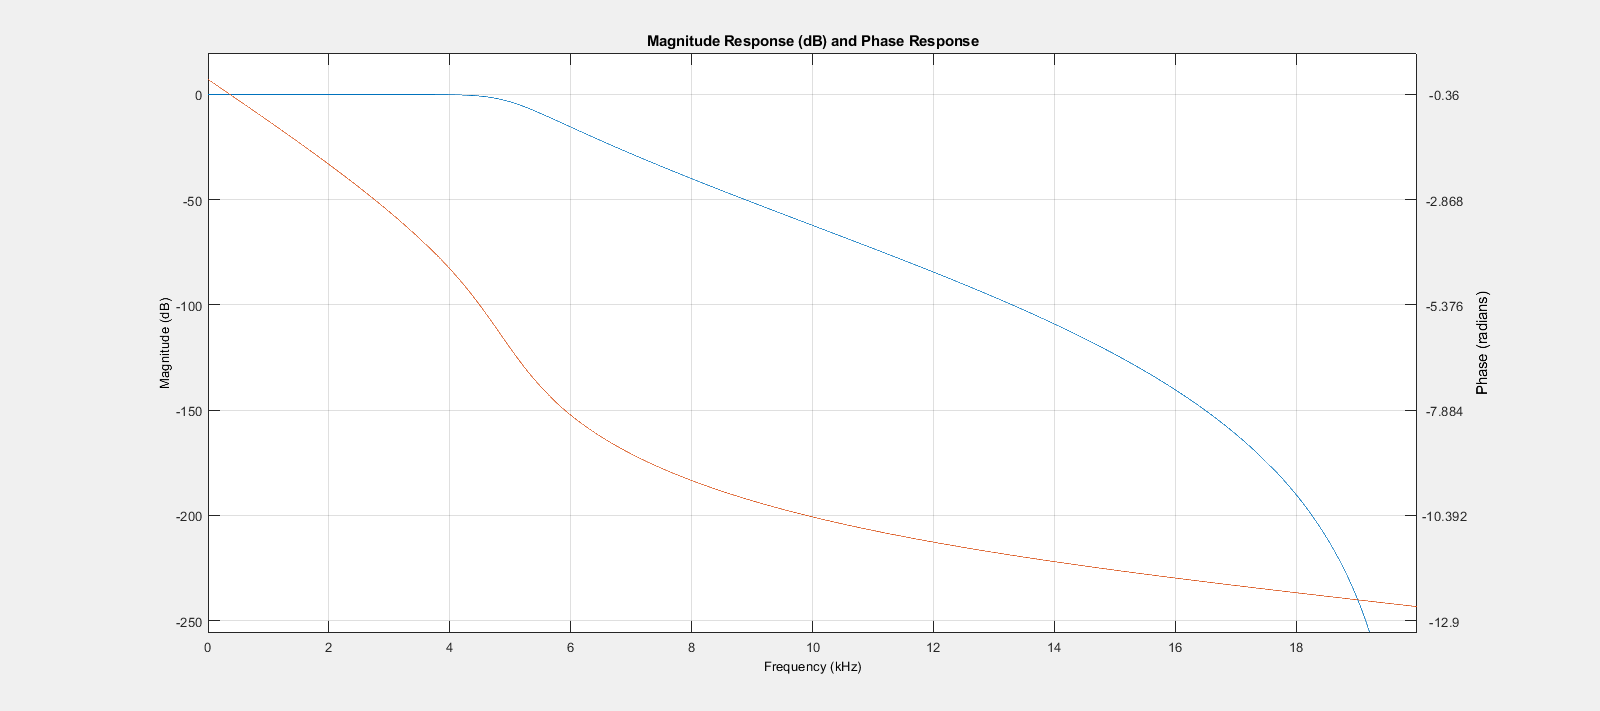

fvtool(lpIIR, 'freq')

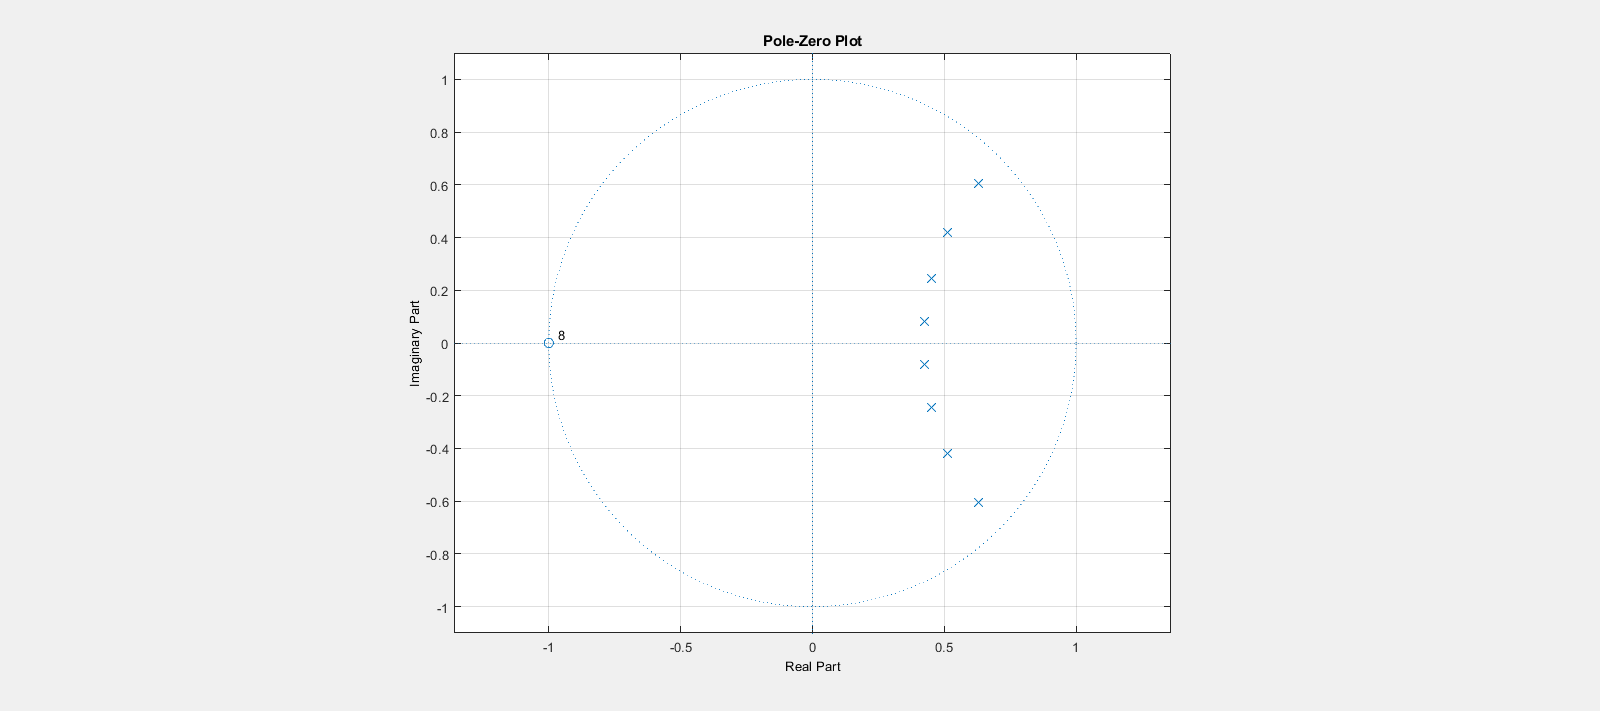

fvtool(lpIIR,'polezero')

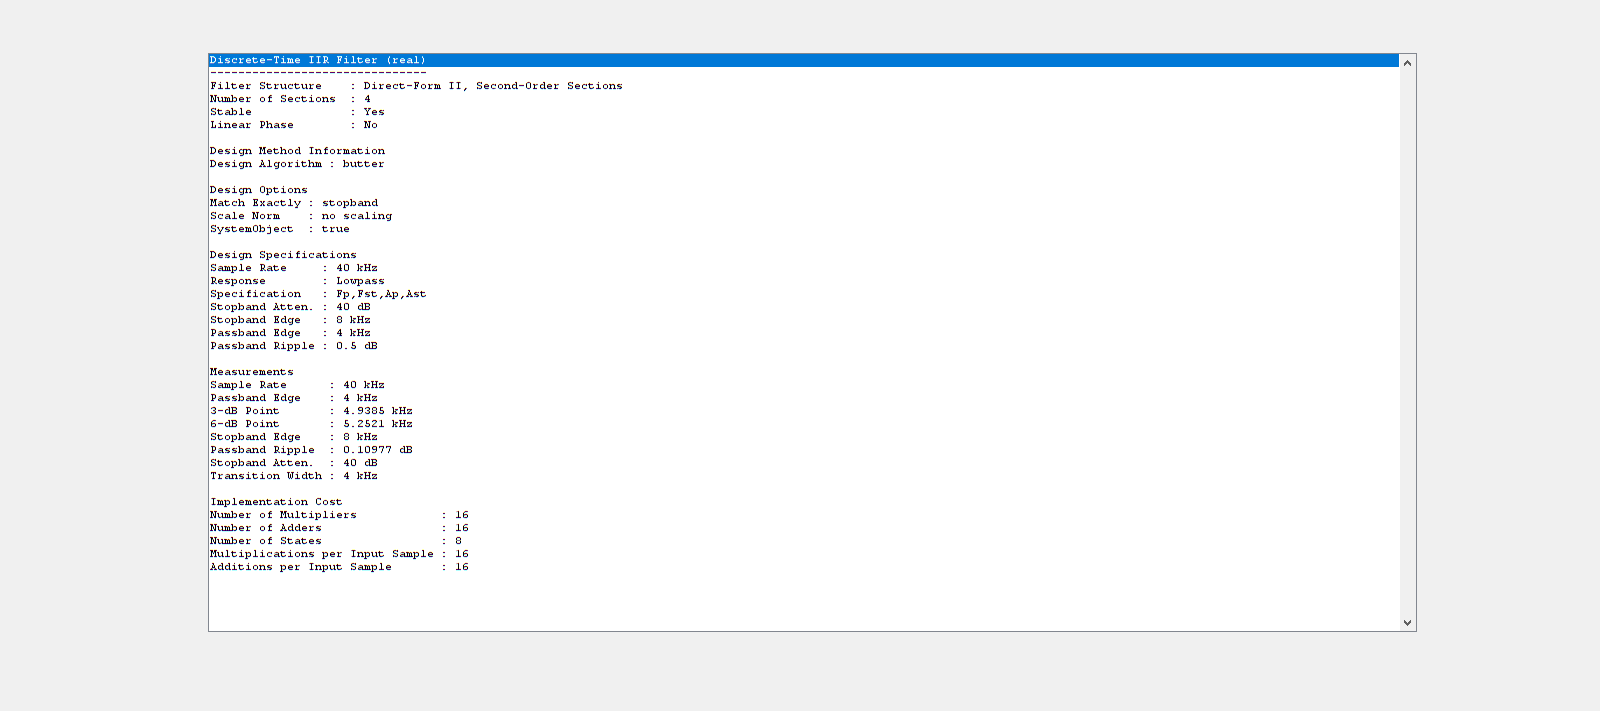

fvtool(lpIIR,'info')

Q 1.2]

Fs = 40000;     %40kHz sampling
Fpass = 4000;   %4kHz passband 
Fstop = 8000;   %8 kHz stopband
Rpass = 0.5;    %Passband ripple = 0.5dB    
Astop = 40;     %Stopband attenuation = 40dB

filtSpecs = fdesign.lowpass(Fpass,Fstop,Rpass,Astop,Fs); %Creating a system object for storing filter specifications
lpIIR = design(filtSpecs,'cheby1','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.lowpass (Fp,Fst,Ap,Ast):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin
multistage



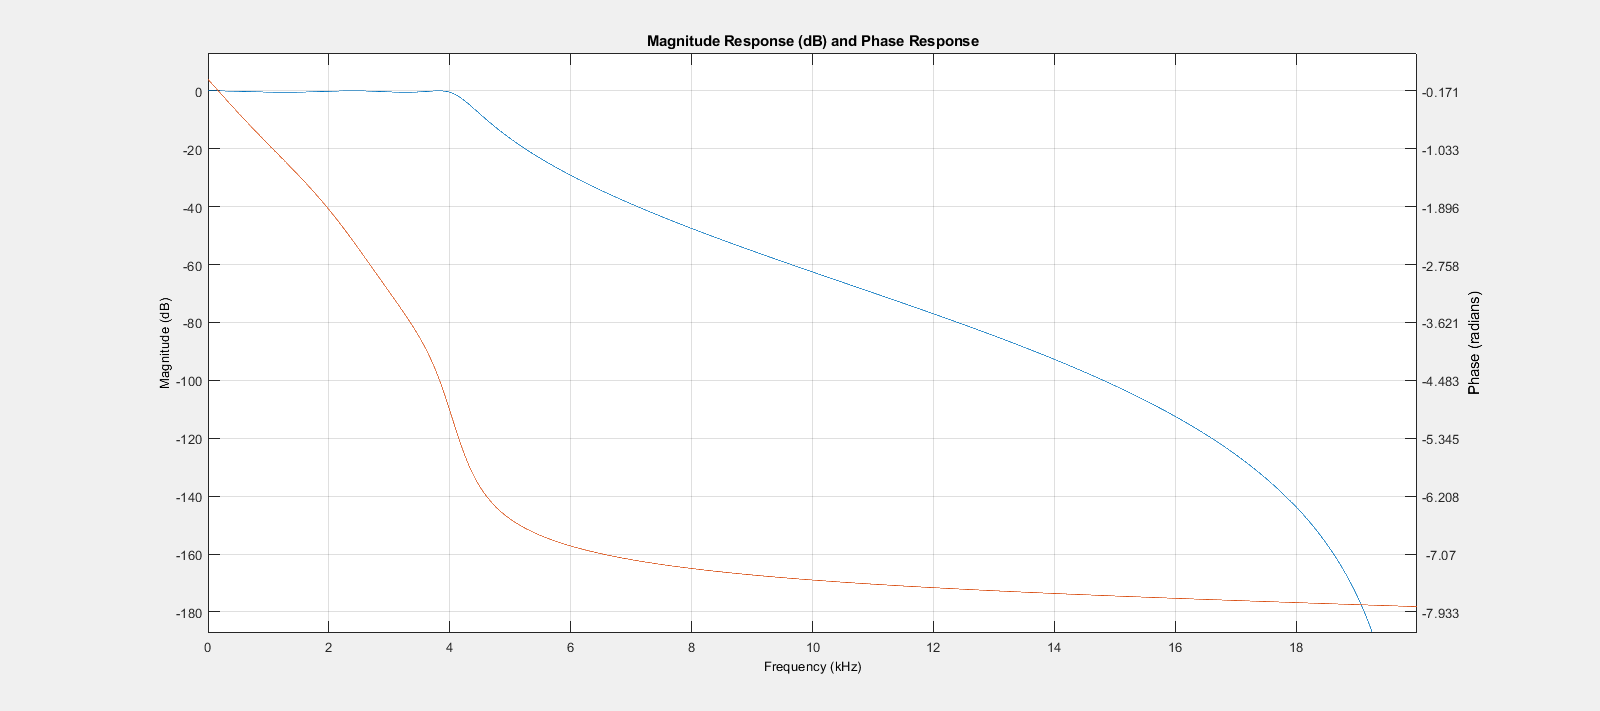

fvtool(lpIIR, 'freq')

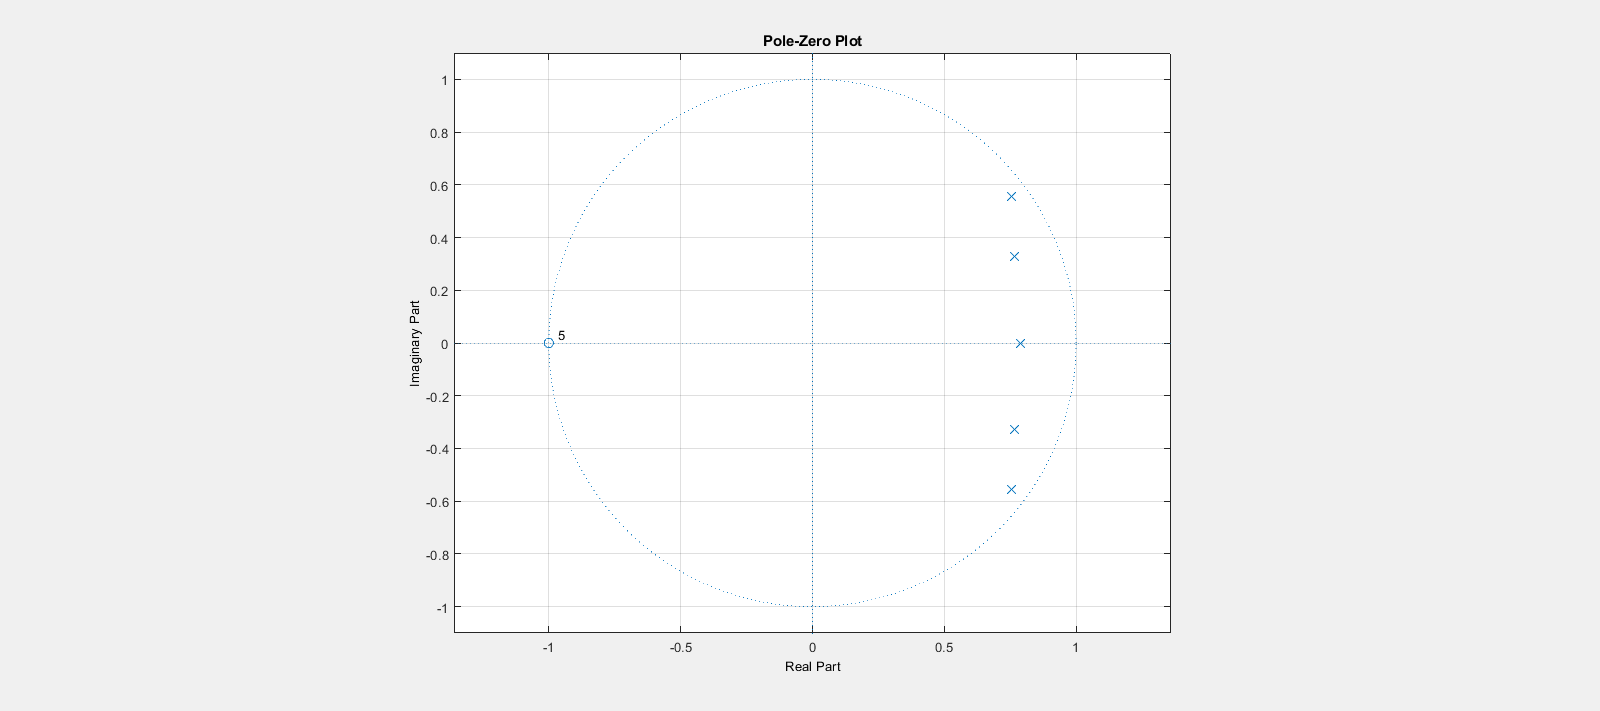

fvtool(lpIIR,'polezero')

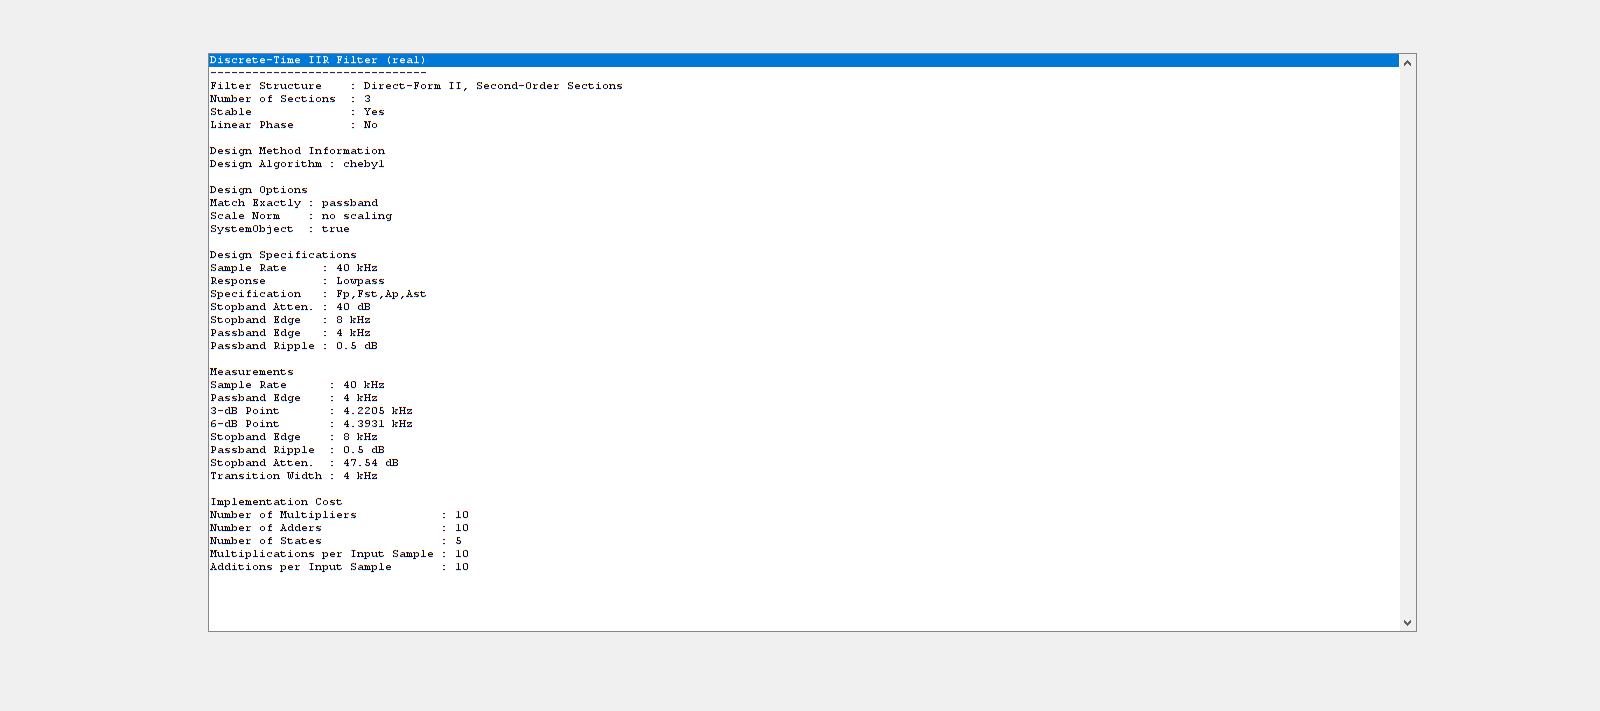

fvtool(lpIIR,'info')

Q 1.3]

Fs = 40000;     %40kHz sampling
Fpass = 4000;   %4kHz passband 
Fstop = 8000;   %8 kHz stopband
Rpass = 0.5;    %Passband ripple = 0.5dB    
Astop = 40;     %Stopband attenuation = 40dB

filtSpecs = fdesign.lowpass(Fpass,Fstop,Rpass,Astop,Fs);
lpIIR = design(filtSpecs,'cheby2','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.lowpass (Fp,Fst,Ap,Ast):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin
multistage



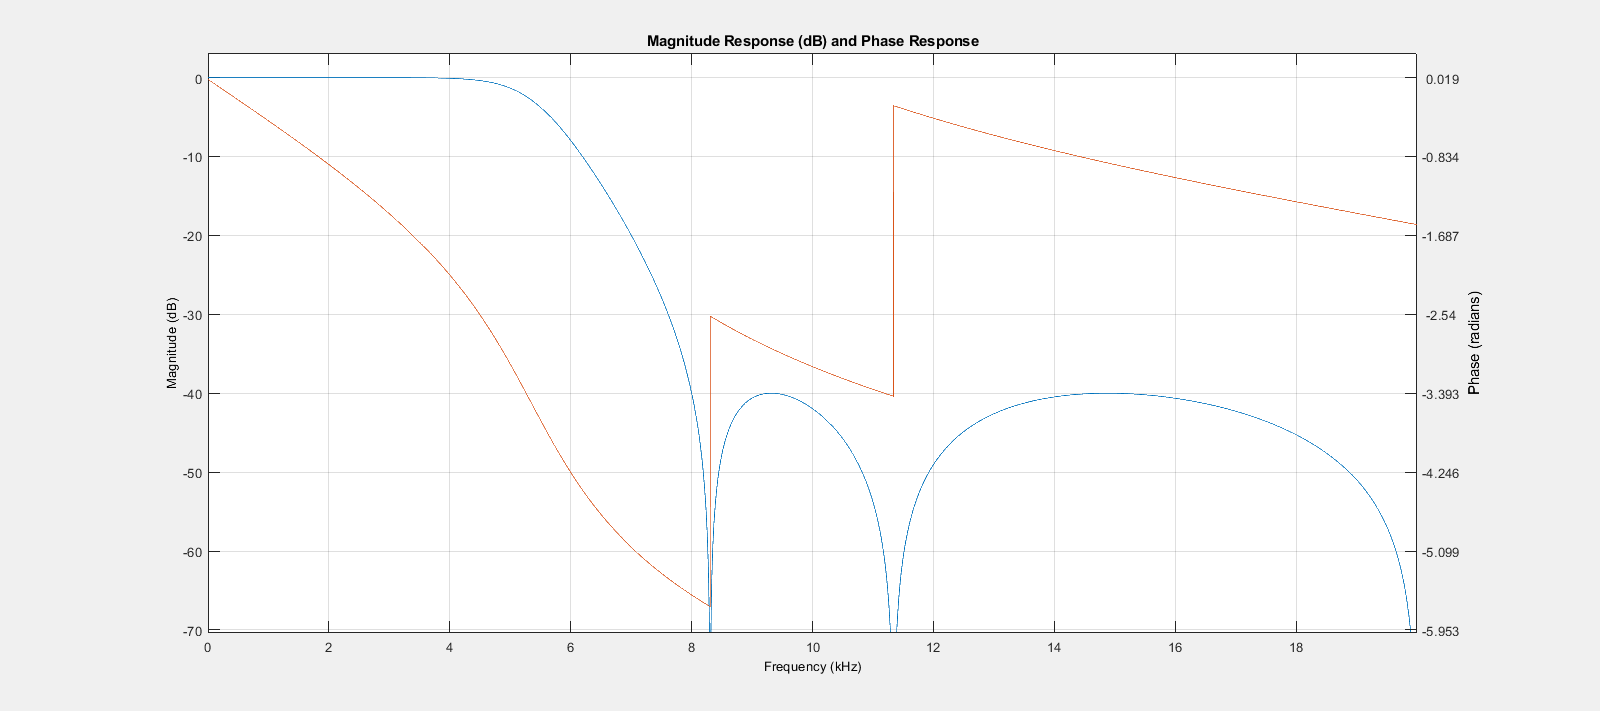

fvtool(lpIIR, 'freq')

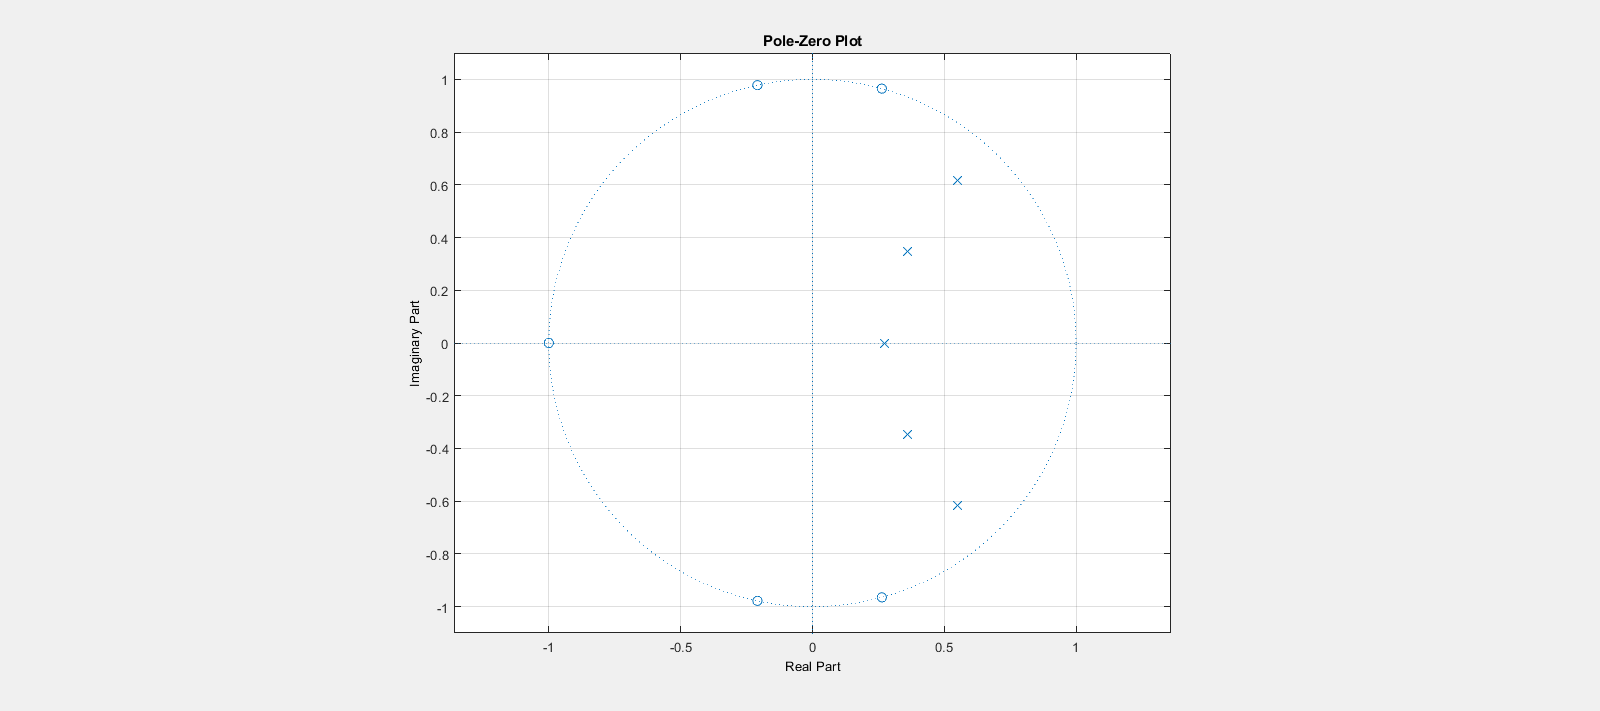

fvtool(lpIIR,'polezero')

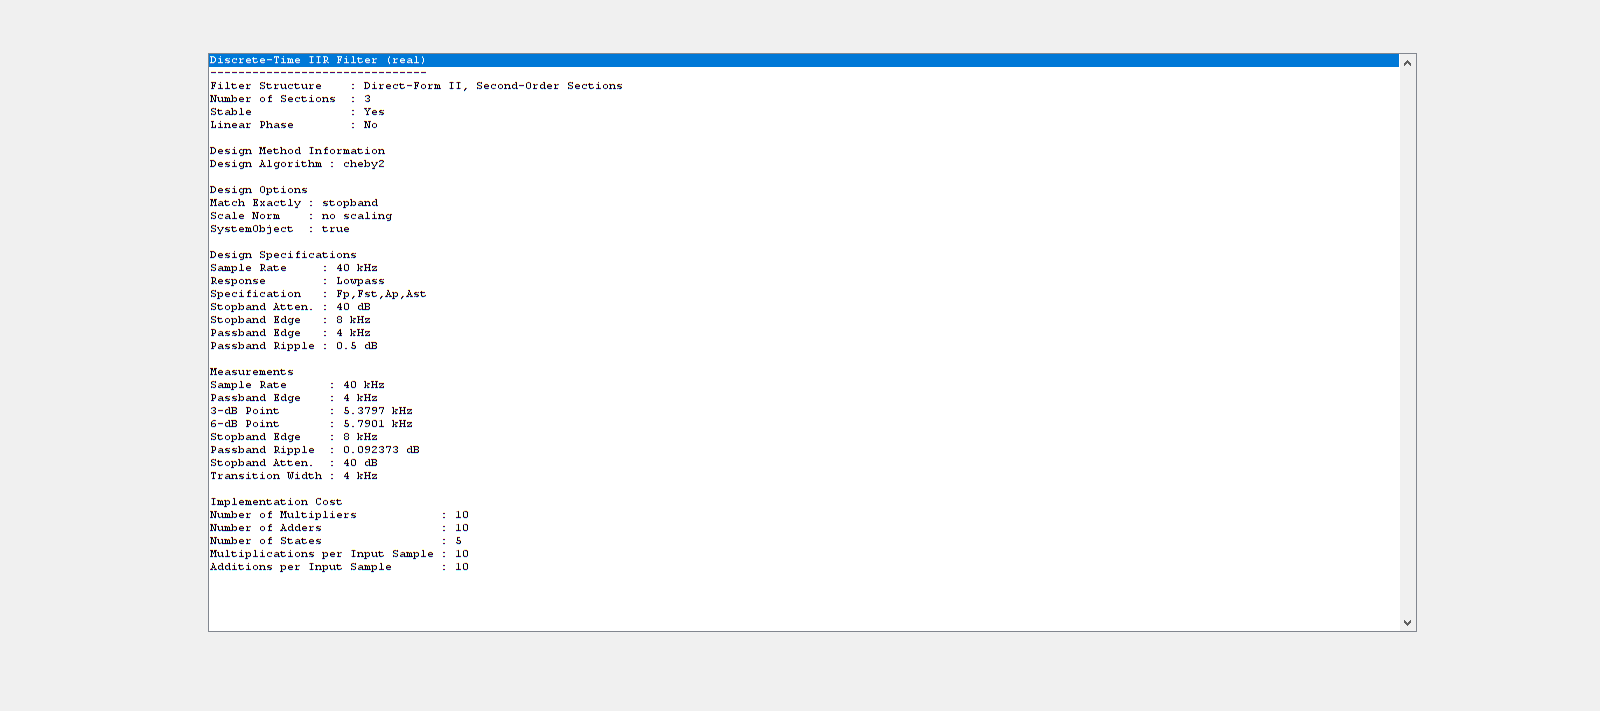

fvtool(lpIIR,'info')

Q 1.4]

Fs = 40000;     %40kHz sampling
Fpass = 4000;   %4kHz passband 
Fstop = 8000;   %8 kHz stopband
Rpass = 0.5;    %Passband ripple = 0.5dB    
Astop = 40;     %Stopband attenuation = 40dB

filtSpecs = fdesign.lowpass(Fpass,Fstop,Rpass,Astop,Fs);
lpIIR = design(filtSpecs,'ellip','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.lowpass (Fp,Fst,Ap,Ast):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin
multistage



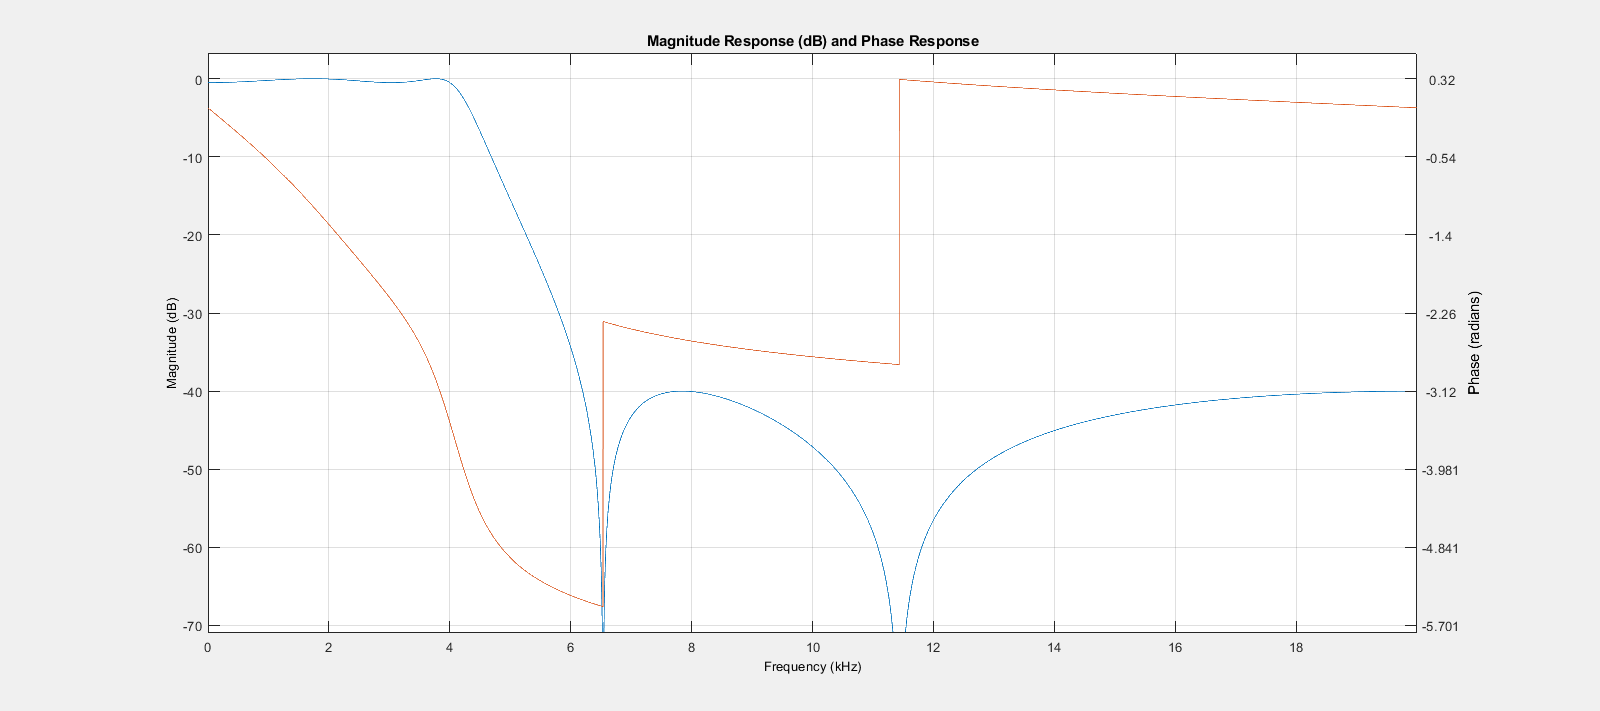

fvtool(lpIIR, 'freq')

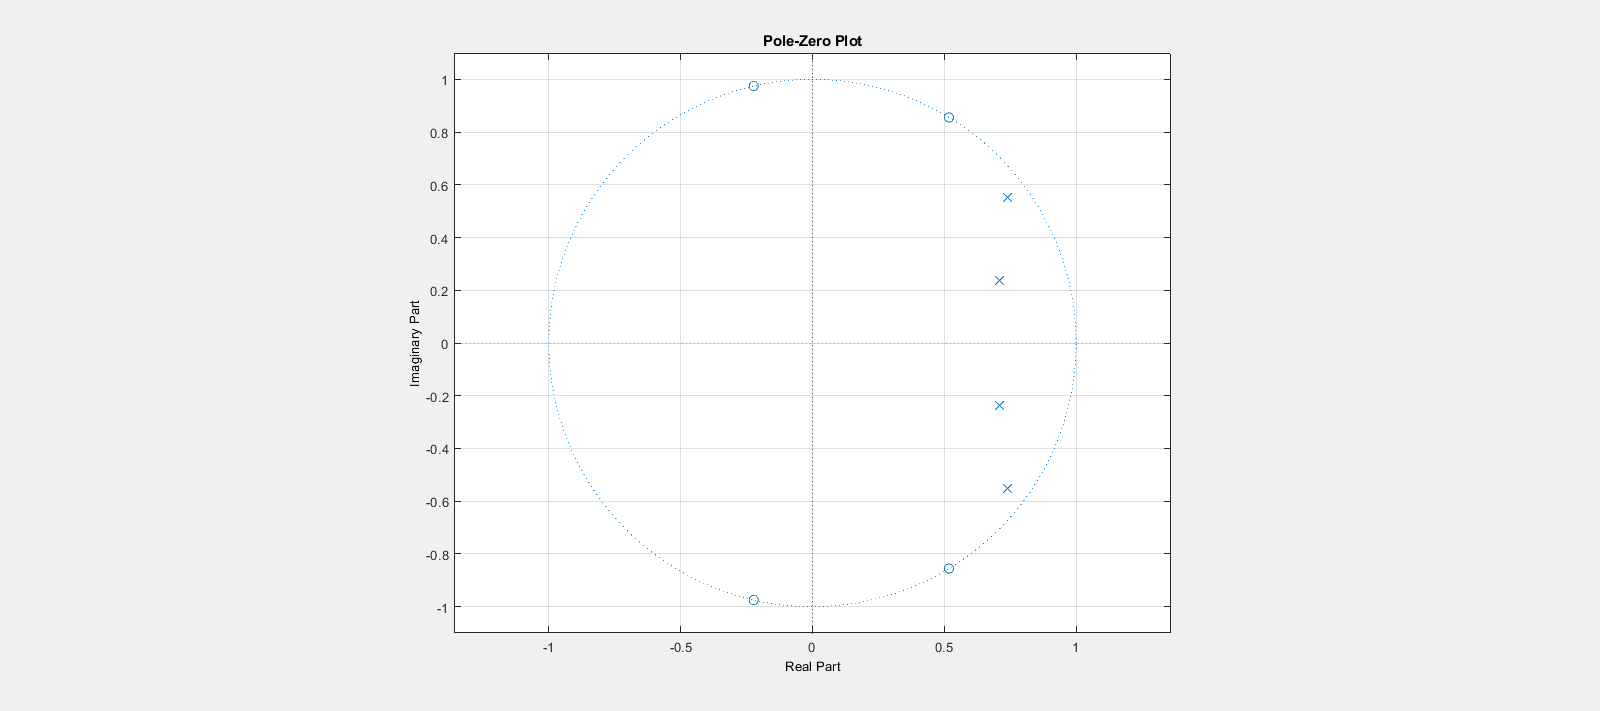

fvtool(lpIIR,'polezero')

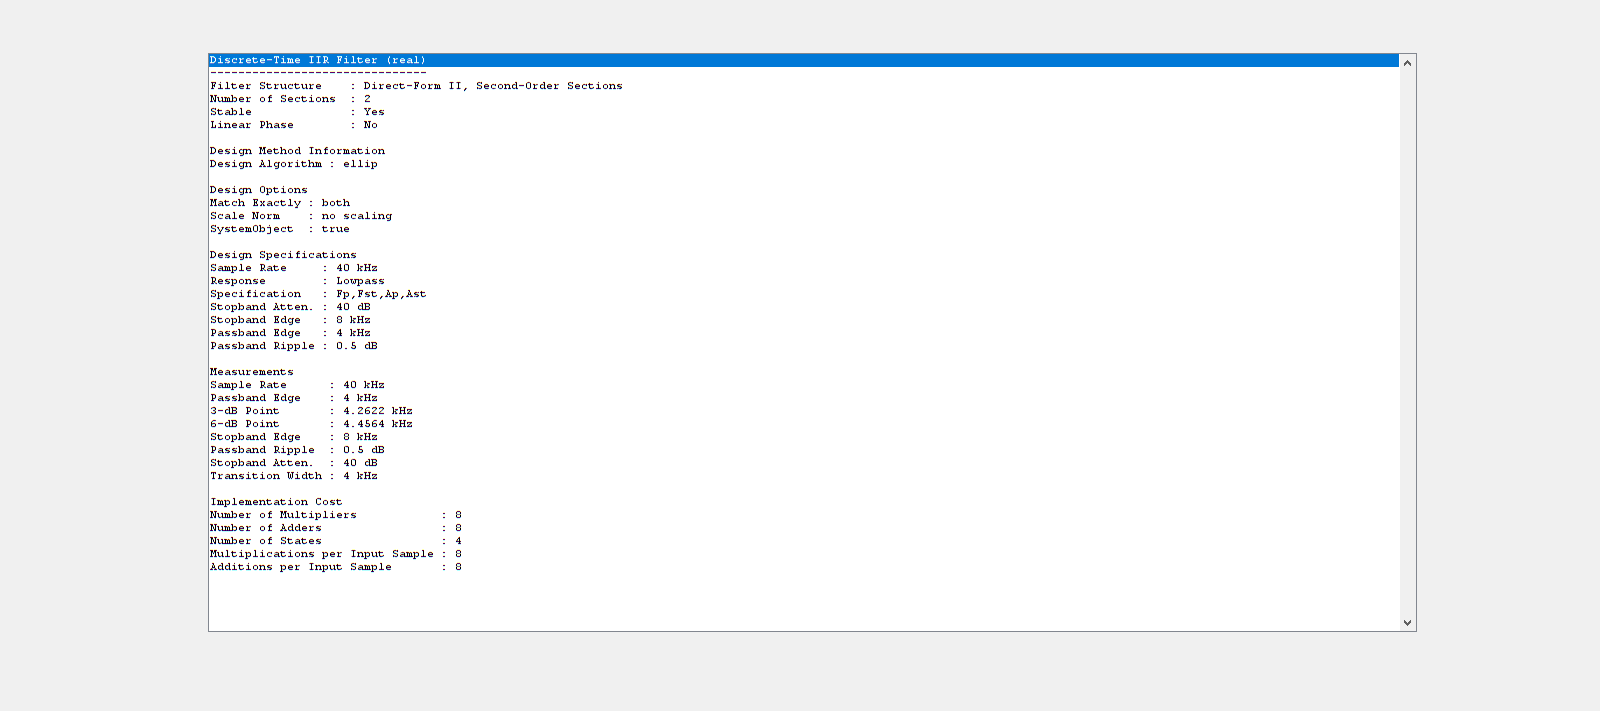

fvtool(lpIIR,'info')

Q 2.1]

Fs = 3500;      %3.5kHz sampling
Fpass = 1050;   %1050Hz passband 
Fstop = 600;   %600Hz stopband
Rpass = 1;    %Passband ripple = 1dB    
Astop = 50;     %Stopband attenuation = 50dB

filtSpecs = fdesign.highpass(Fstop/Fs,Fpass/Fs,Astop,Rpass);
designmethods(filtSpecs)



Design Methods for class fdesign.highpass (Fst,Fp,Ast,Ap):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin



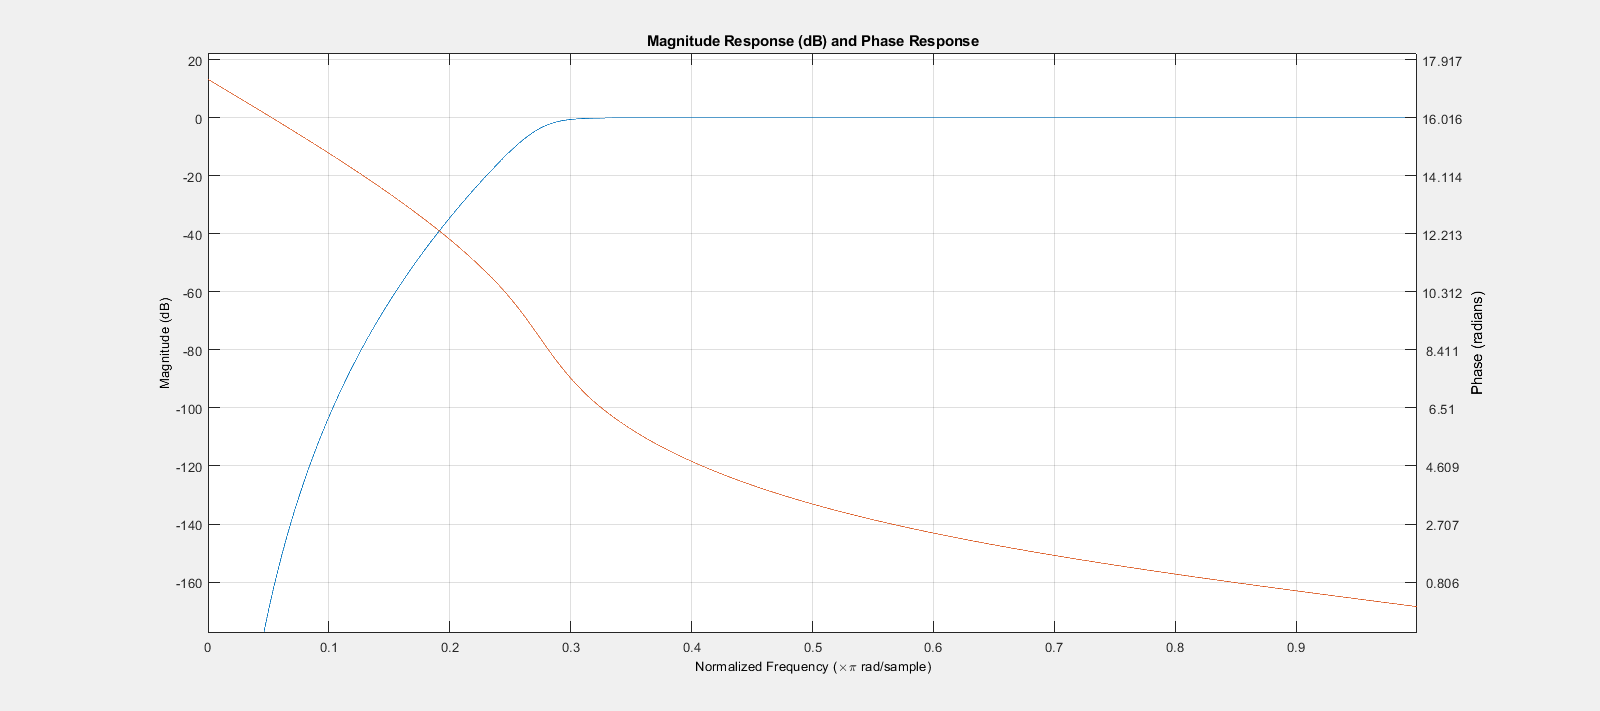

hpIIR = design(filtSpecs,'butter','SystemObject',true);

fvtool(hpIIR, 'freq')

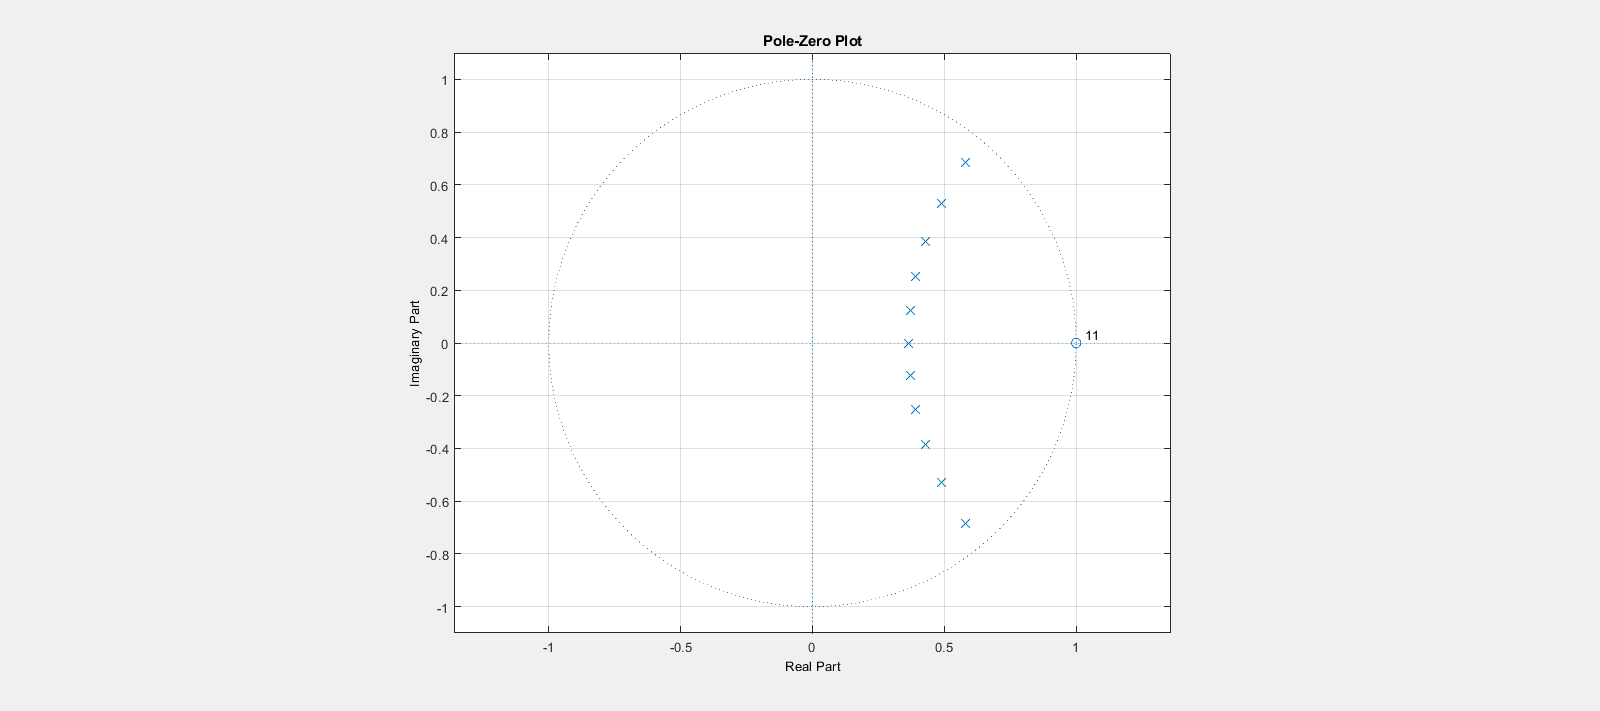

fvtool(hpIIR,'polezero')

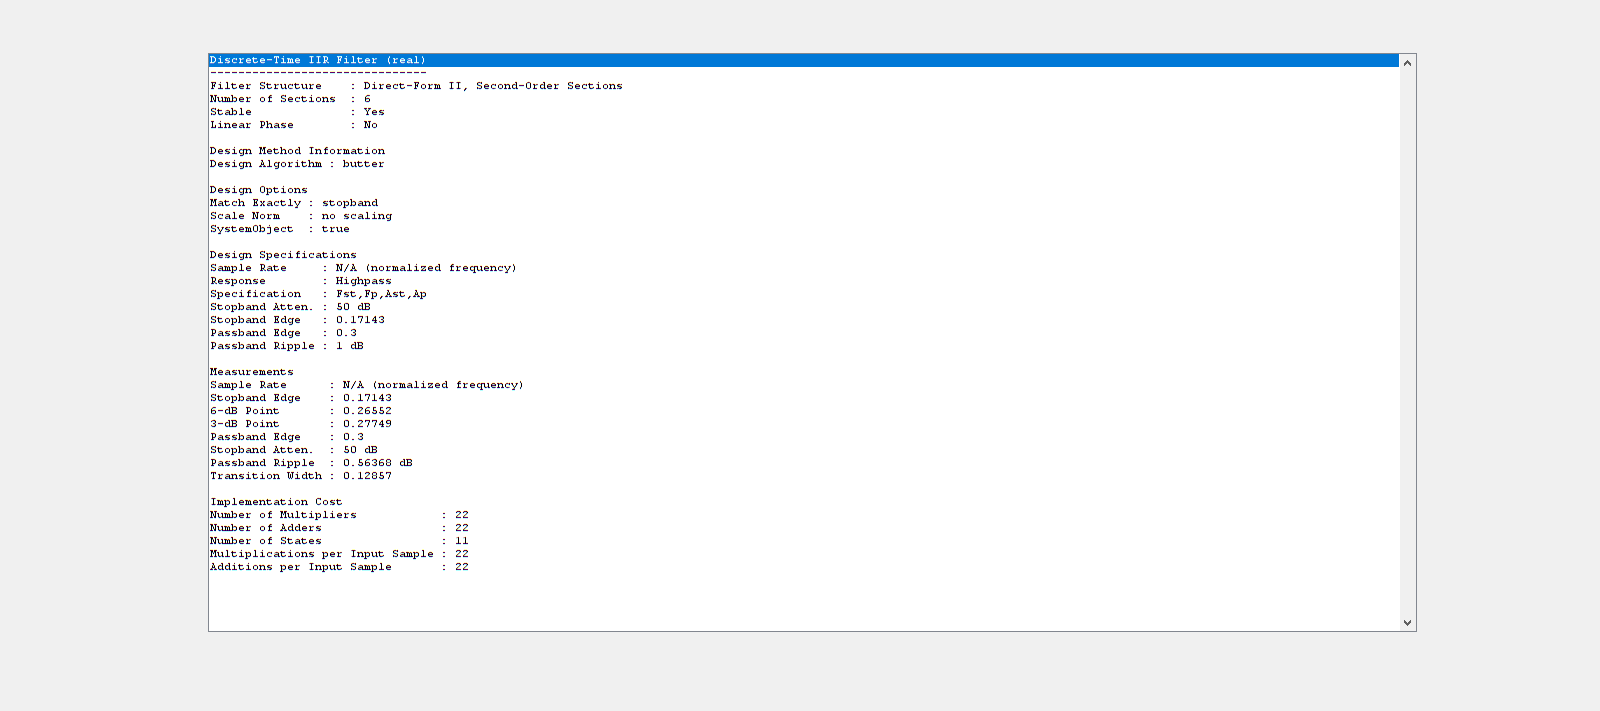

fvtool(hpIIR,'info')

Q 2.2]

Fs = 3500;      %3.5kHz sampling
Fpass = 1050;   %1050Hz passband 
Fstop = 600;   %600Hz stopband
Rpass = 1;    %Passband ripple = 1dB    
Astop = 50;     %Stopband attenuation = 50dB

filtSpecs = fdesign.highpass(Fstop/Fs,Fpass/Fs,Astop,Rpass);
designmethods(filtSpecs)



Design Methods for class fdesign.highpass (Fst,Fp,Ast,Ap):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin



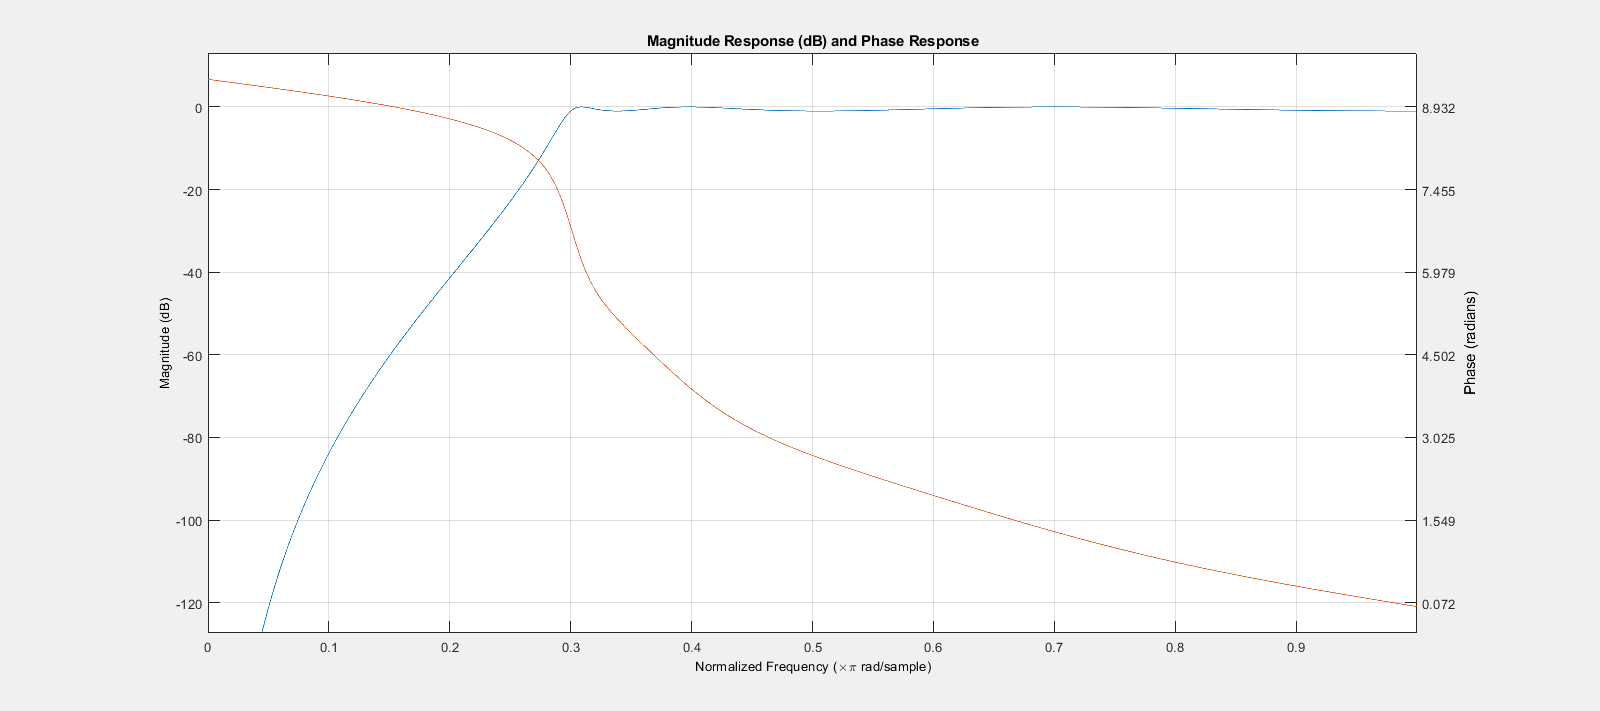

hpIIR = design(filtSpecs,'cheby1','SystemObject',true);

fvtool(hpIIR, 'freq')

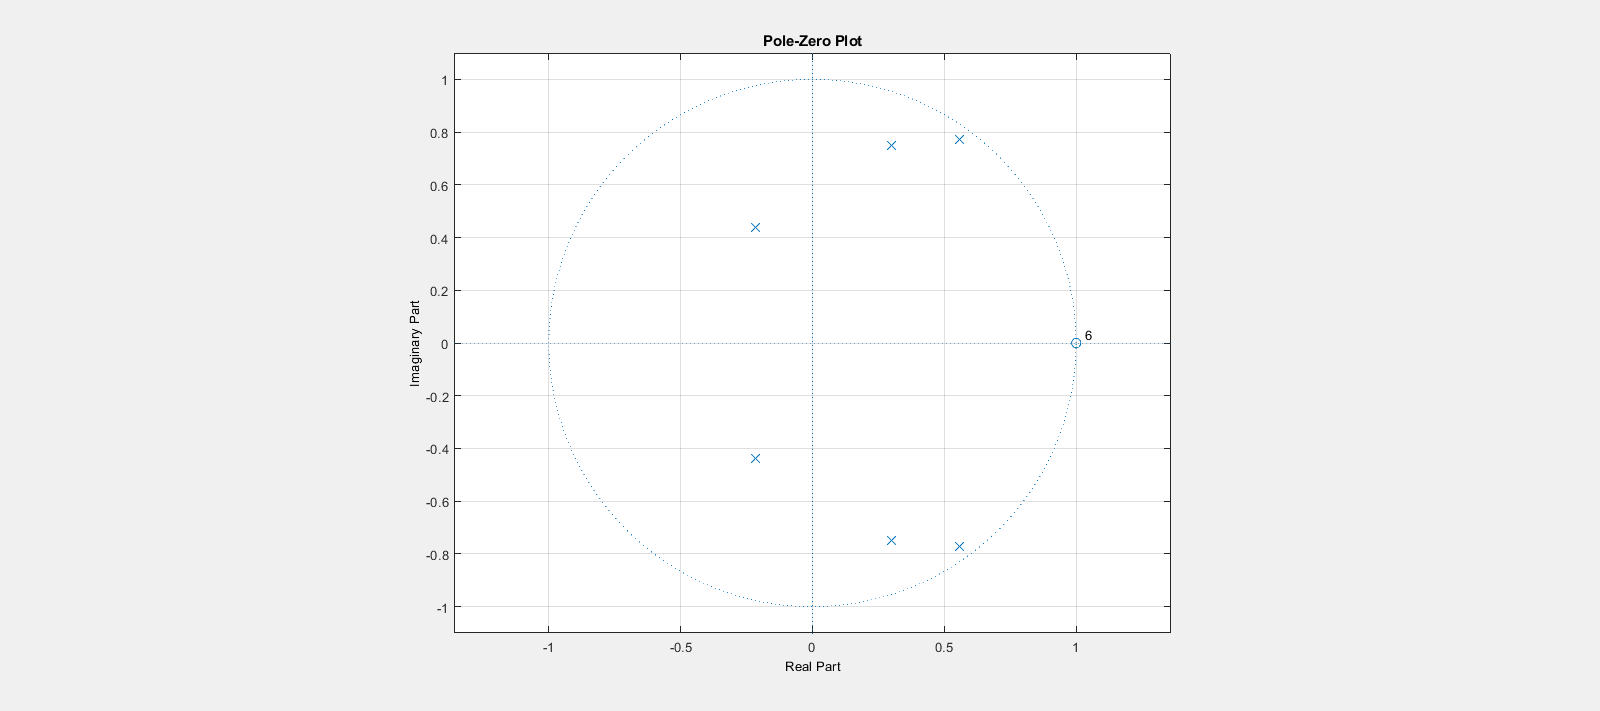

fvtool(hpIIR,'polezero')

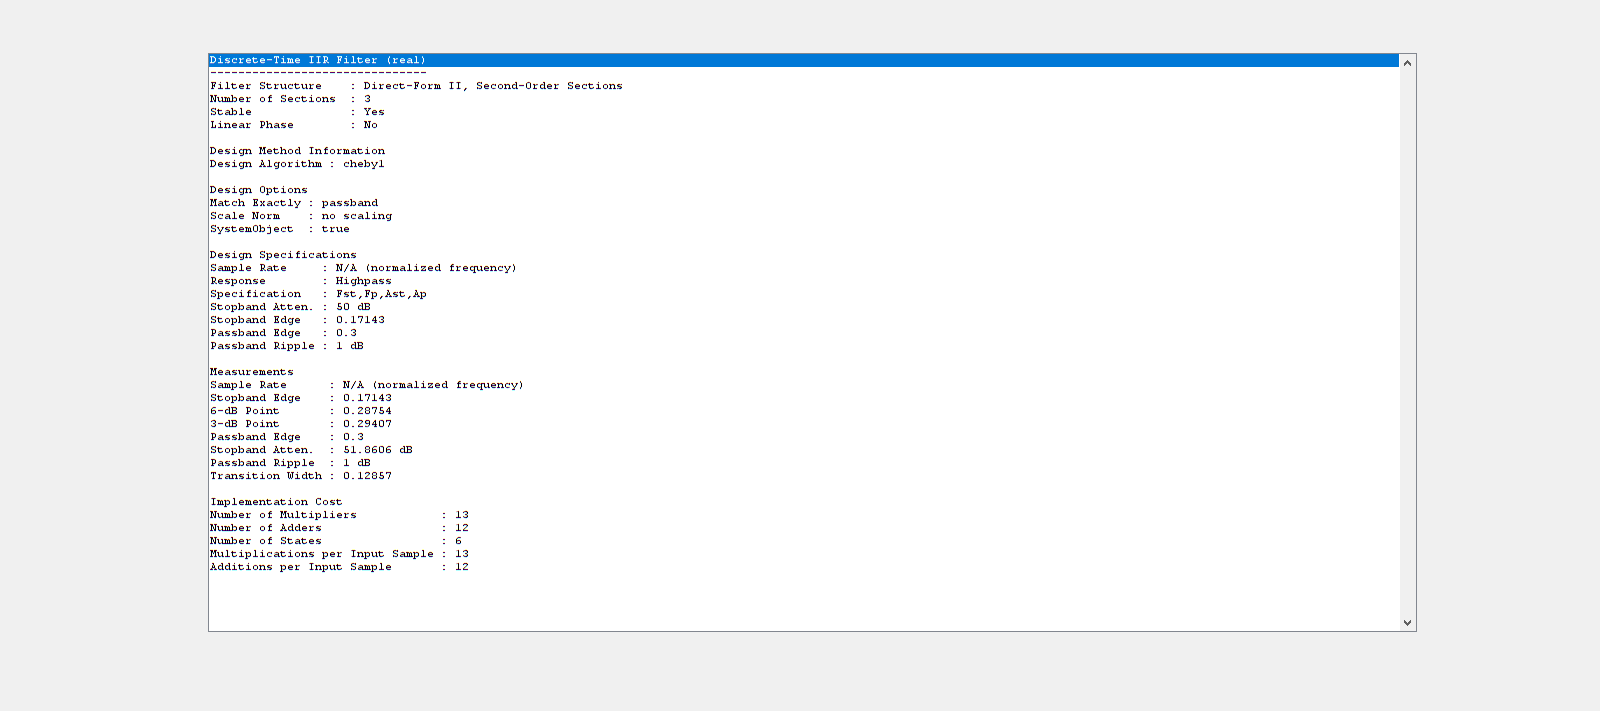

fvtool(hpIIR,'info')

Q 2.3]

Fs = 3500;      %3.5kHz sampling
Fpass = 1050;   %1050Hz passband 
Fstop = 600;    %600Hz stopband
Rpass = 1;      %Passband ripple = 1dB    
Astop = 50;     %Stopband attenuation = 50dB

filtSpecs = fdesign.highpass(Fstop/Fs,Fpass/Fs,Astop,Rpass);
designmethods(filtSpecs)



Design Methods for class fdesign.highpass (Fst,Fp,Ast,Ap):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin



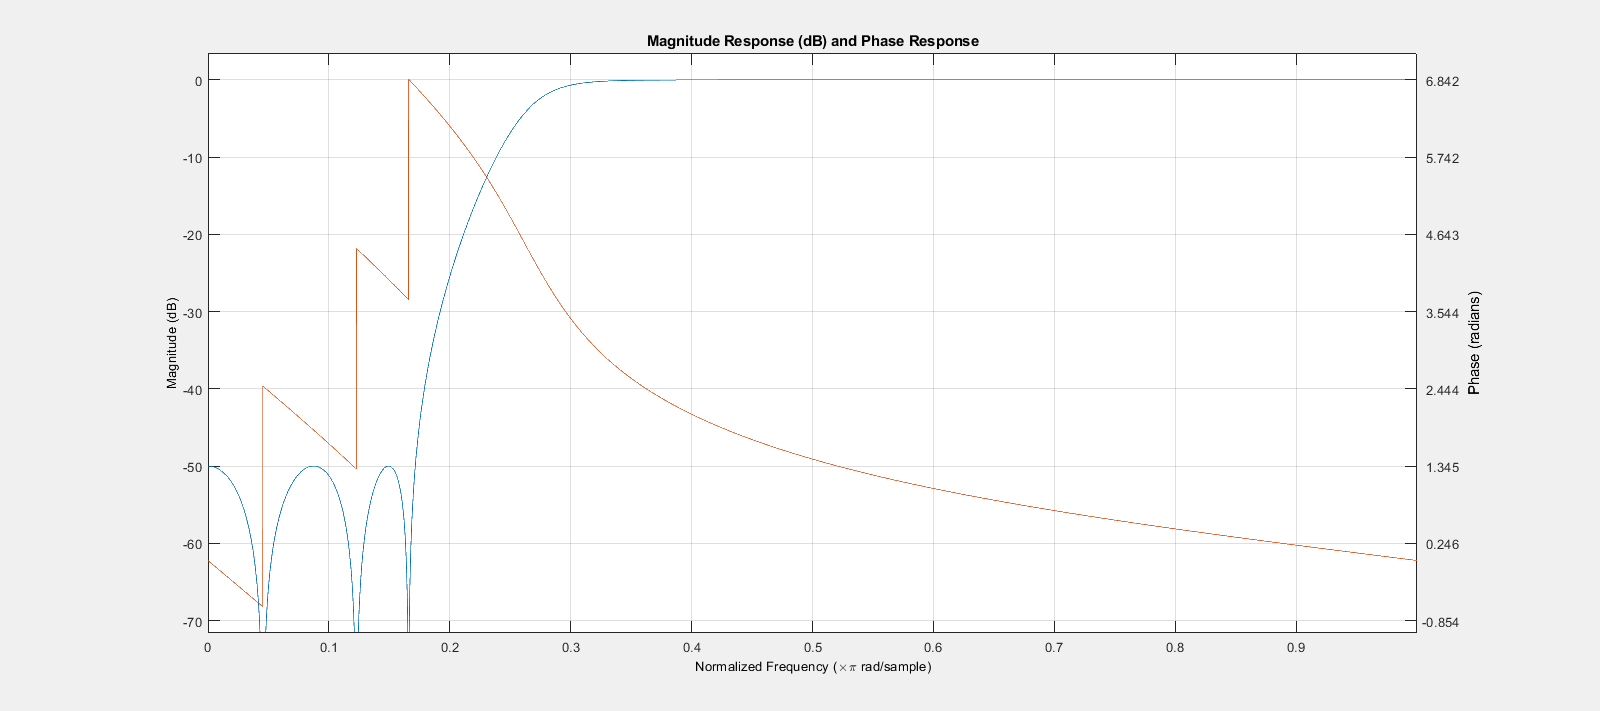

hpIIR = design(filtSpecs,'cheby2','SystemObject',true);

fvtool(hpIIR, 'freq')

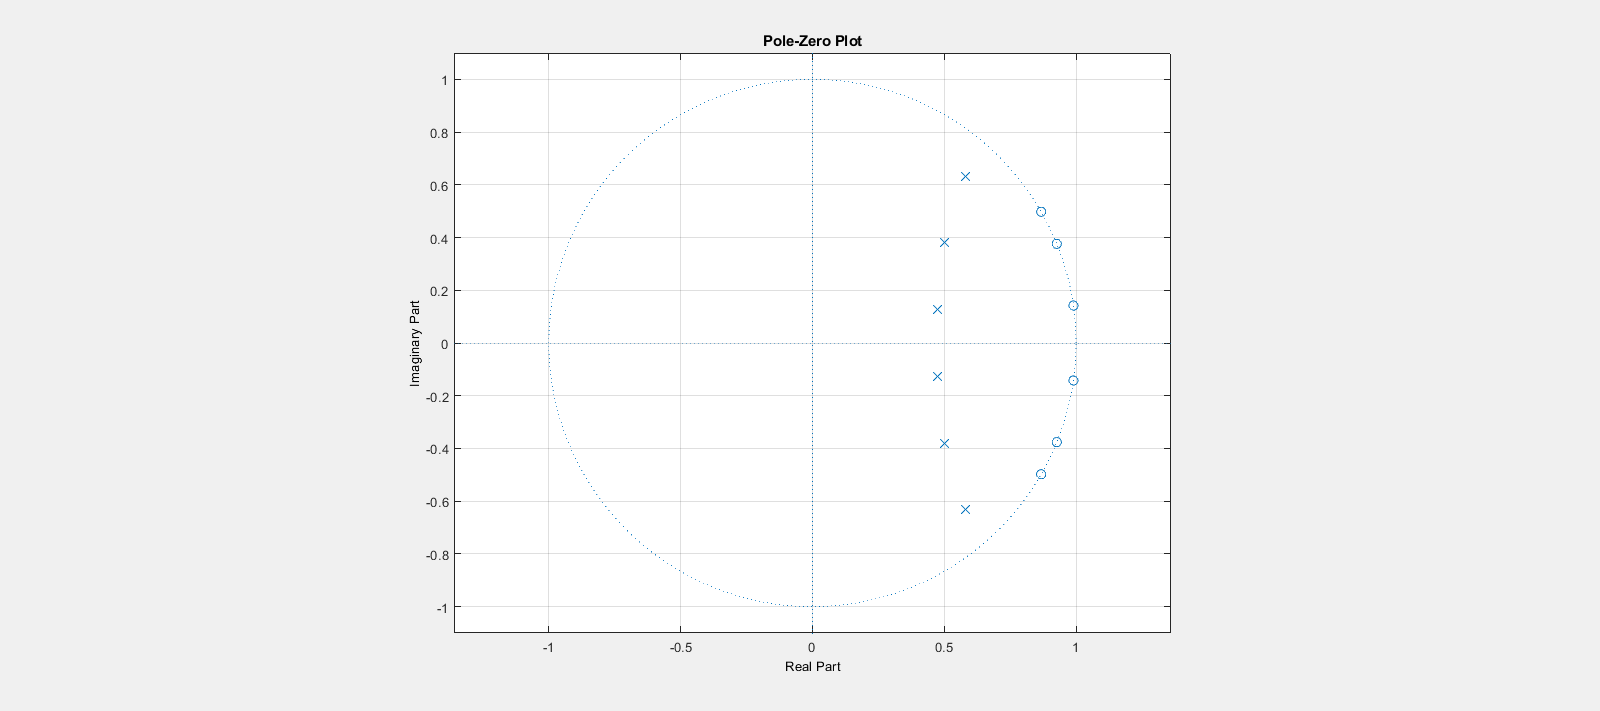

fvtool(hpIIR,'polezero')

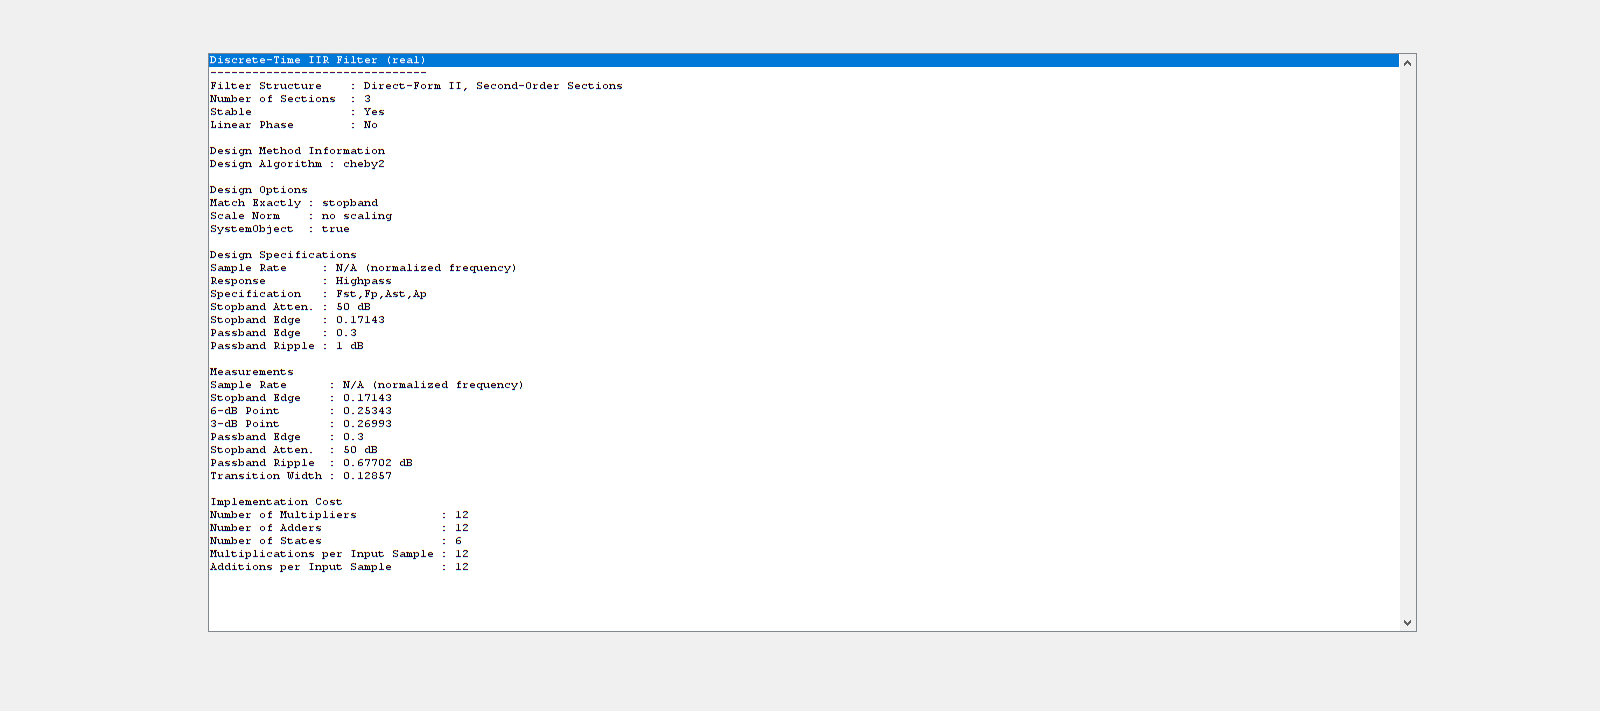

fvtool(hpIIR,'info')

Q 2.4]

Fs = 3500;      %3.5kHz sampling
Fpass = 1050;   %1050Hz passband 
Fstop = 600;    %600Hz stopband
Rpass = 1;      %Passband ripple = 1dB    
Astop = 50;     %Stopband attenuation = 50dB

filtSpecs = fdesign.highpass(Fstop/Fs,Fpass/Fs,Astop,Rpass);
designmethods(filtSpecs)



Design Methods for class fdesign.highpass (Fst,Fp,Ast,Ap):


butter
cheby1
cheby2
ellip
equiripple
ifir
kaiserwin



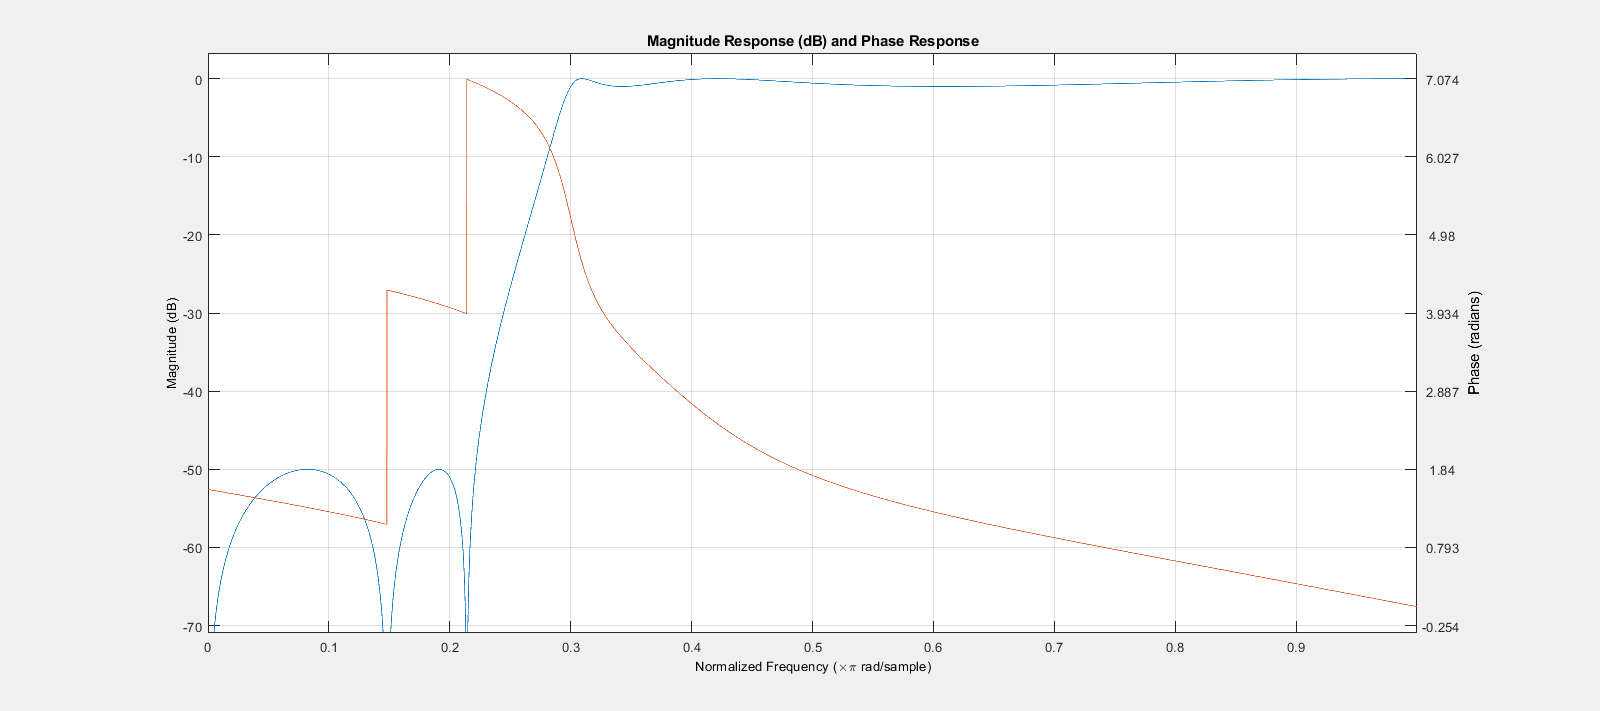

hpIIR = design(filtSpecs,'ellip','SystemObject',true);

fvtool(hpIIR, 'freq')

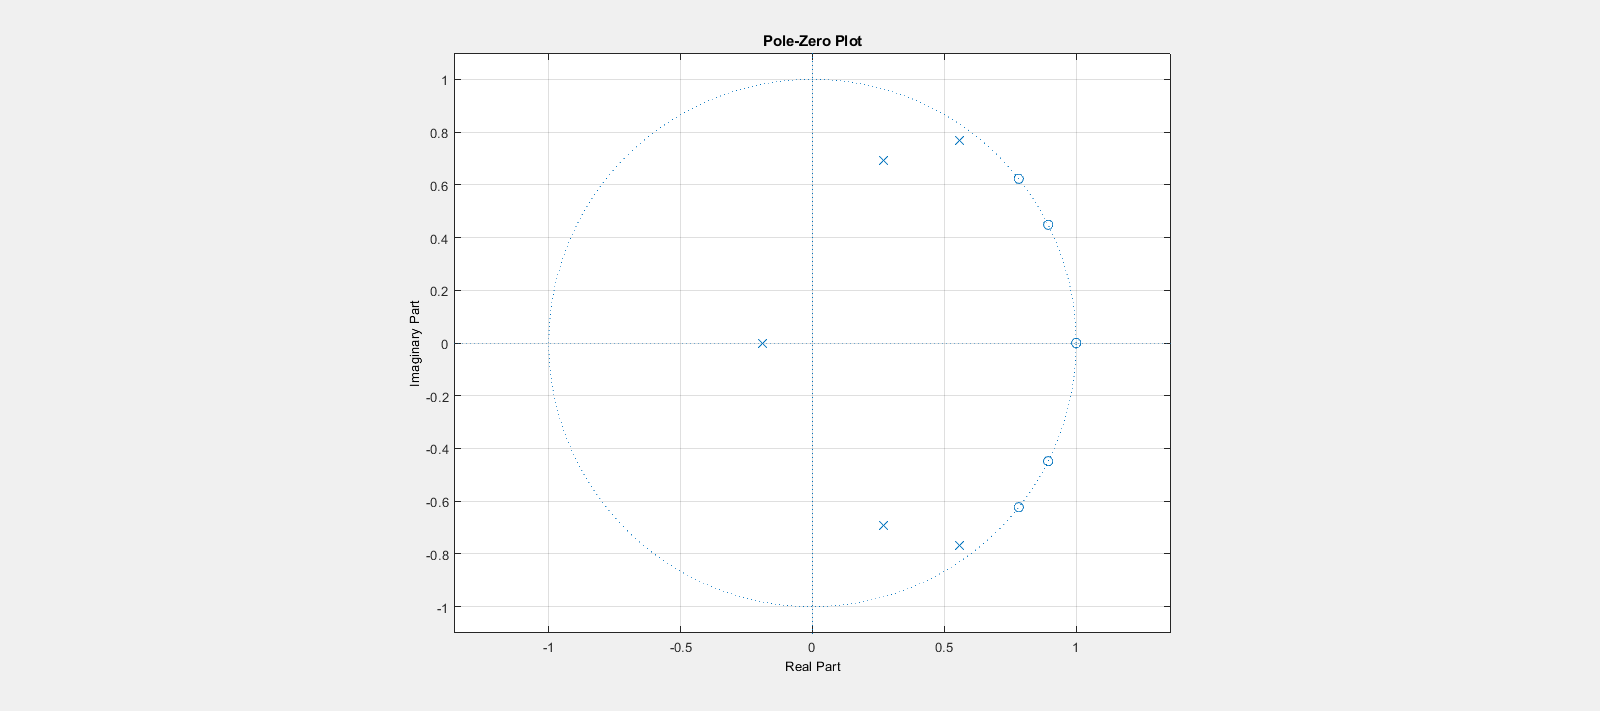

fvtool(hpIIR,'polezero')

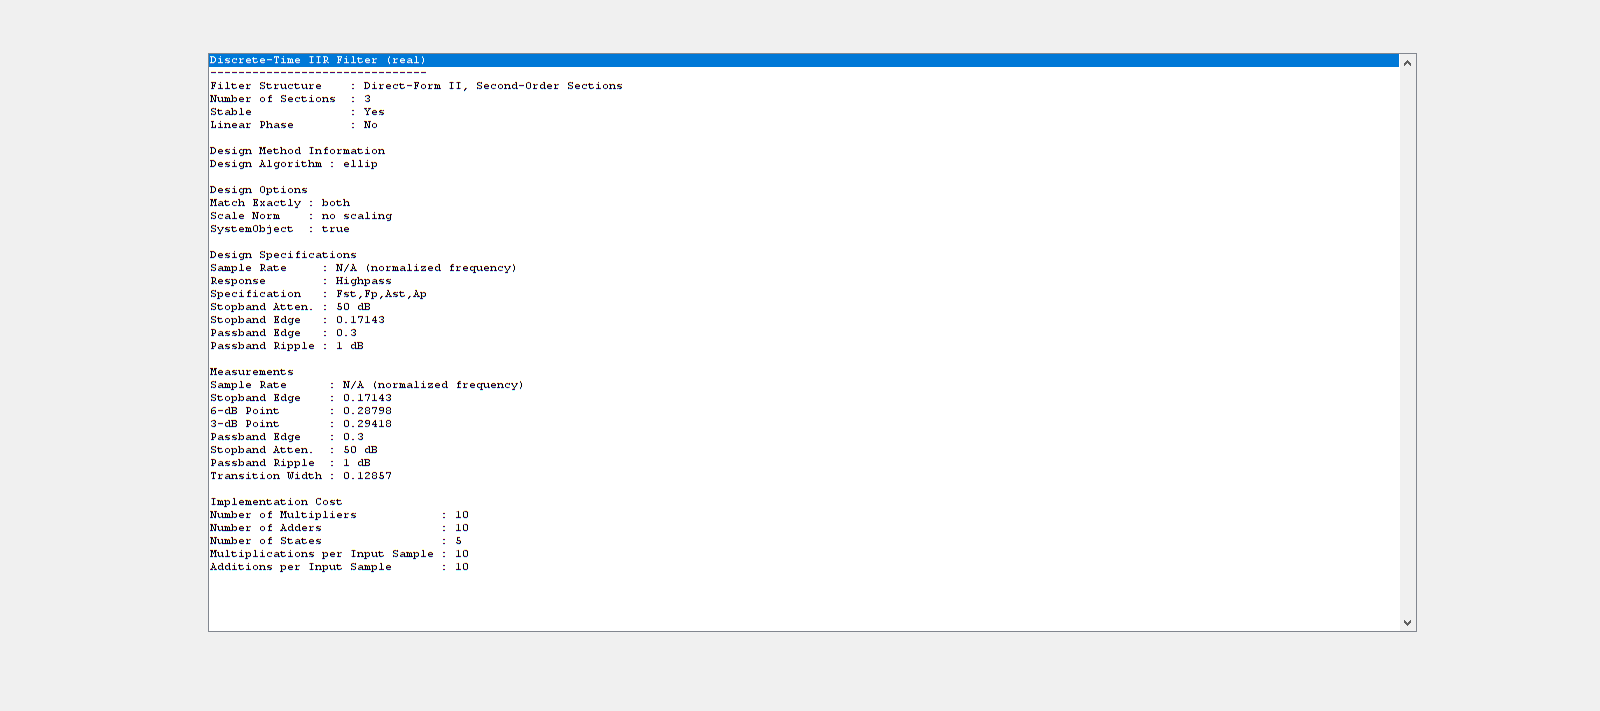

fvtool(hpIIR,'info')

Q 3.1]

% Sampling rate and cutoff frequencies
Fs = 7000;
Fpass1 = 1400;
Fpass2 = 2100;
Fstop1 = 1050;
Fstop2 = 2450;

% Pass band ripple and minimum stop band attenuation
Rp = 0.4;
Astop1 = 50;
% Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2
filtSpecs = fdesign.bandpass(Fstop1,Fpass1,Fpass2,Fstop2,Astop1,Rp,Astop1,Fs);
BpIIR = design(filtSpecs,'butter','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandpass (Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



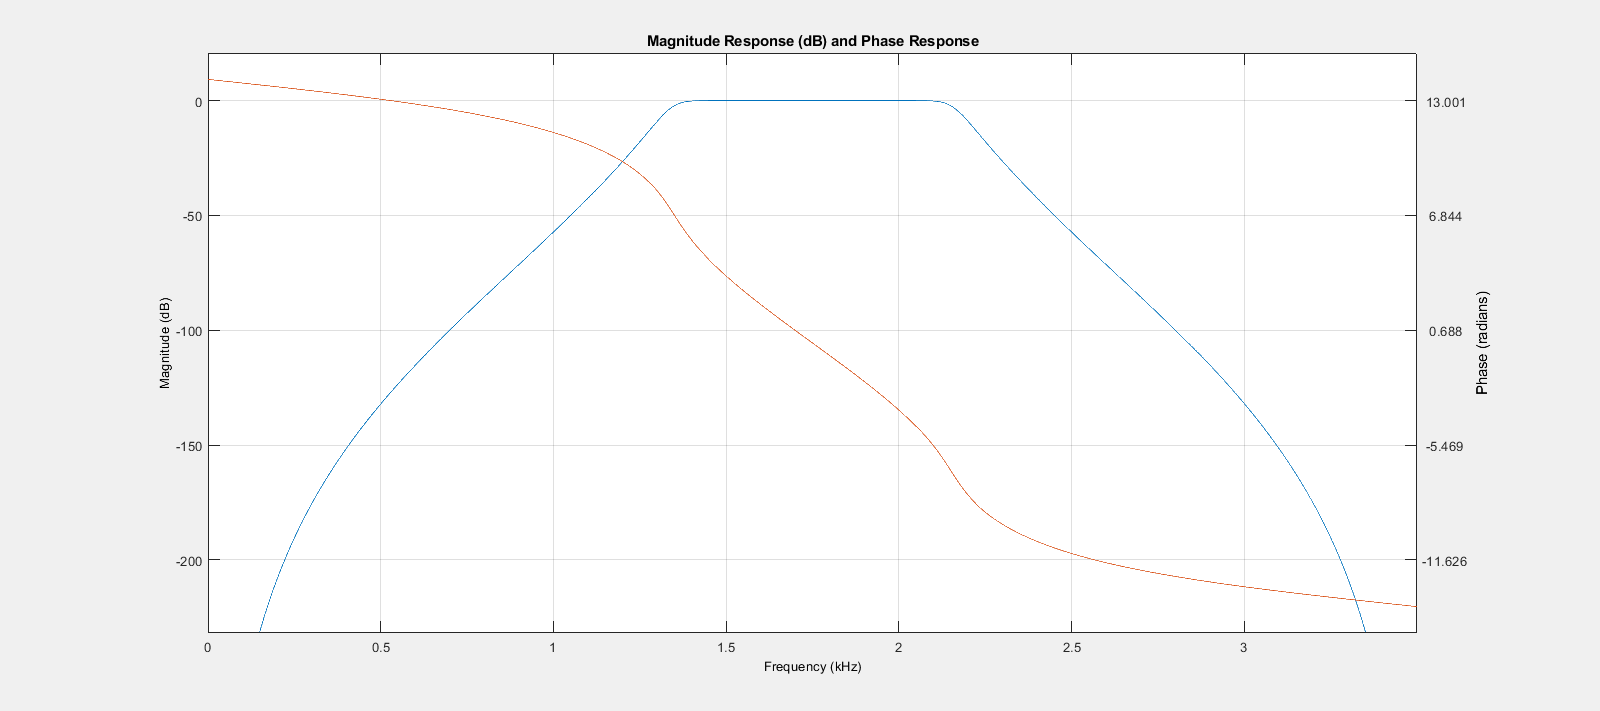

fvtool(BpIIR, 'freq')

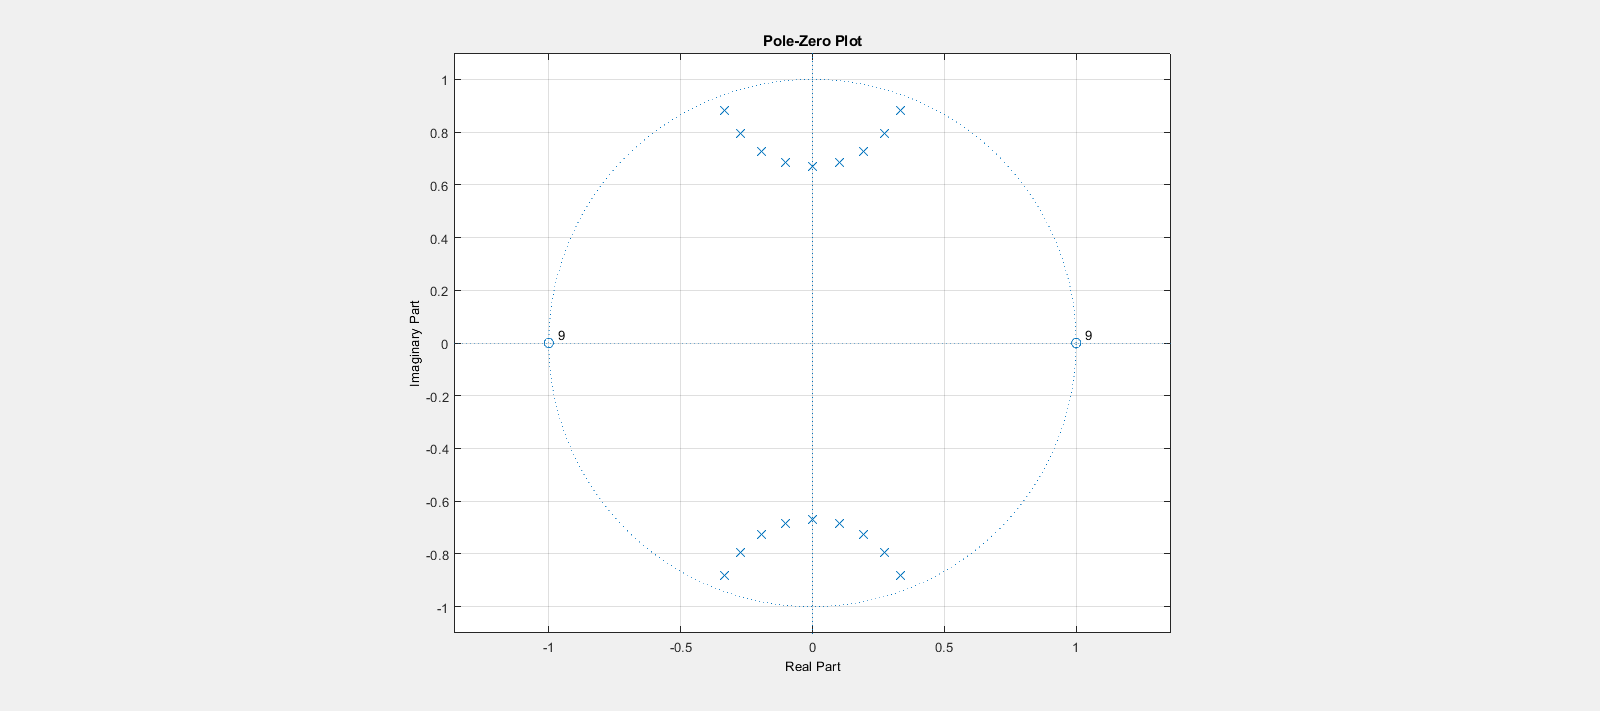

fvtool(BpIIR,'polezero')

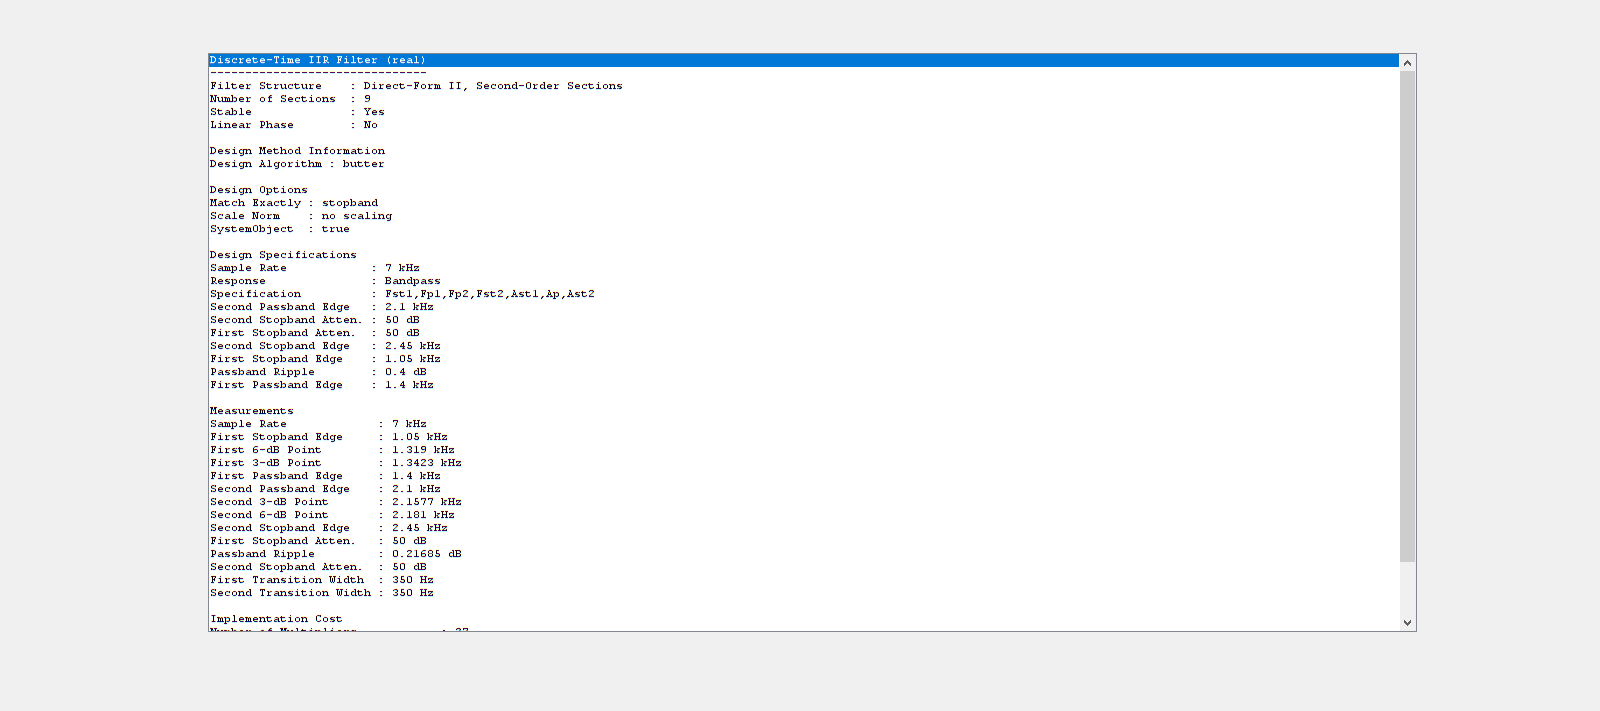

fvtool(BpIIR,'info')

Q3.2]

BpIIR = design(filtSpecs,'cheby1','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandpass (Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



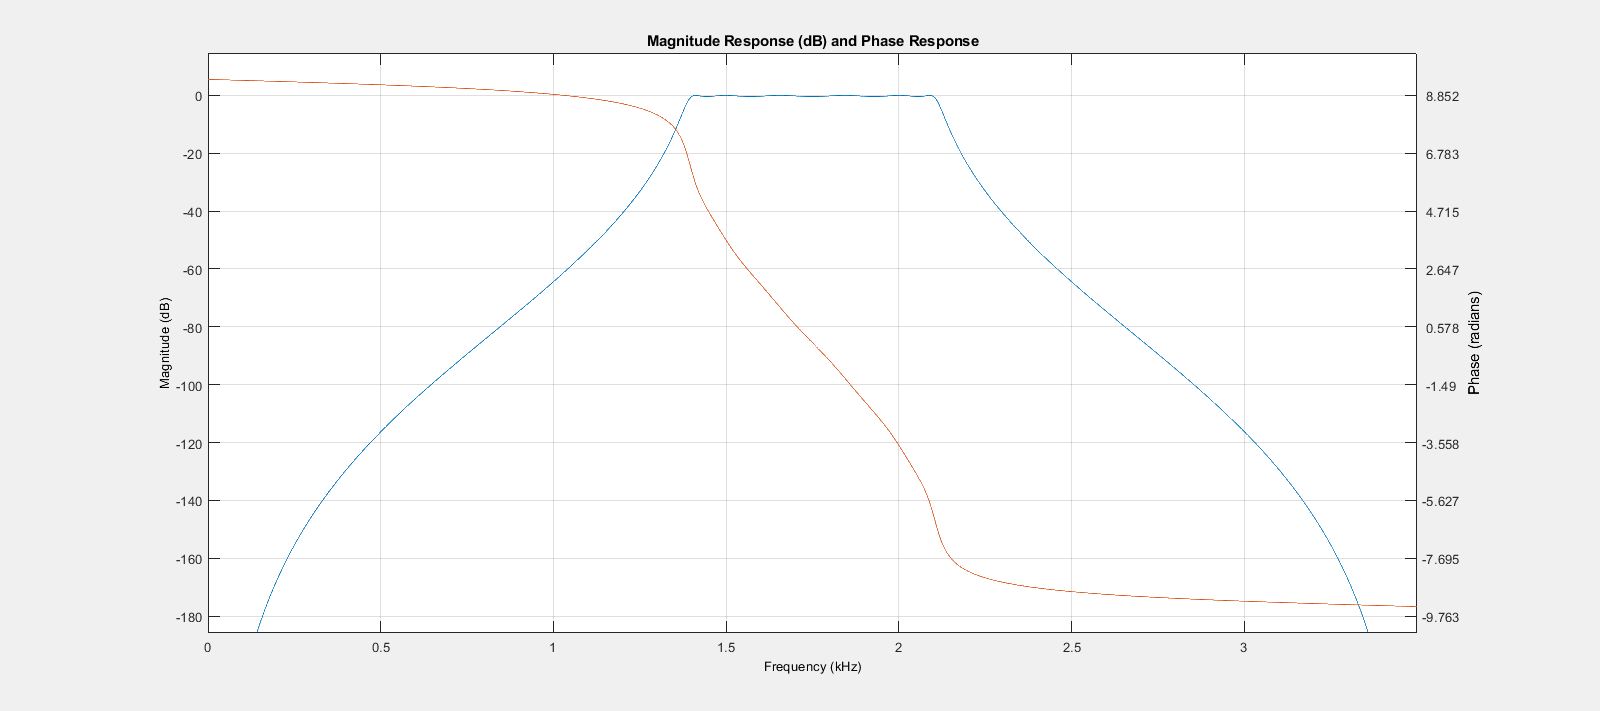

fvtool(BpIIR, 'freq')

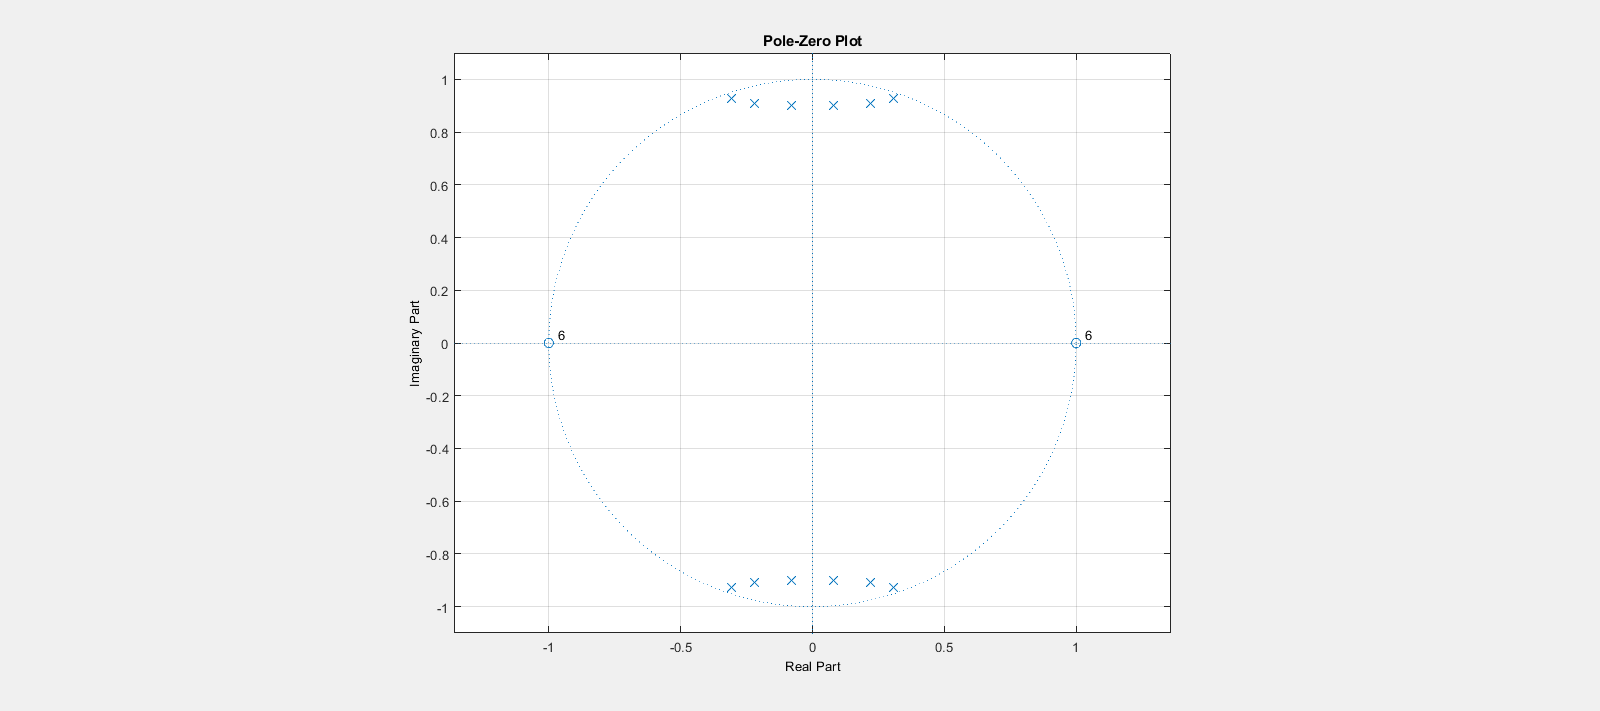

fvtool(BpIIR,'polezero')

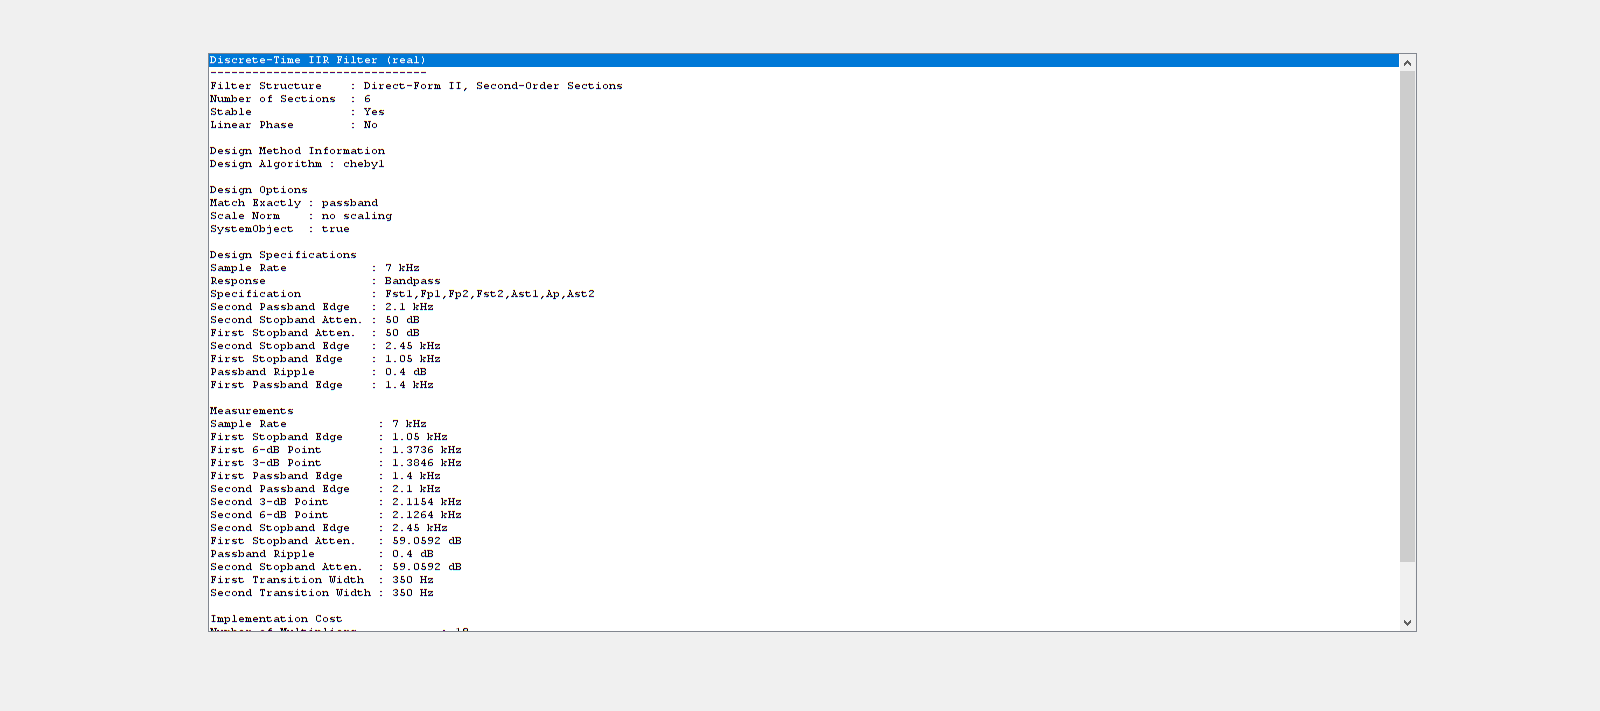

fvtool(BpIIR,'info')

Q3.3]

BpIIR = design(filtSpecs,'cheby2','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandpass (Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



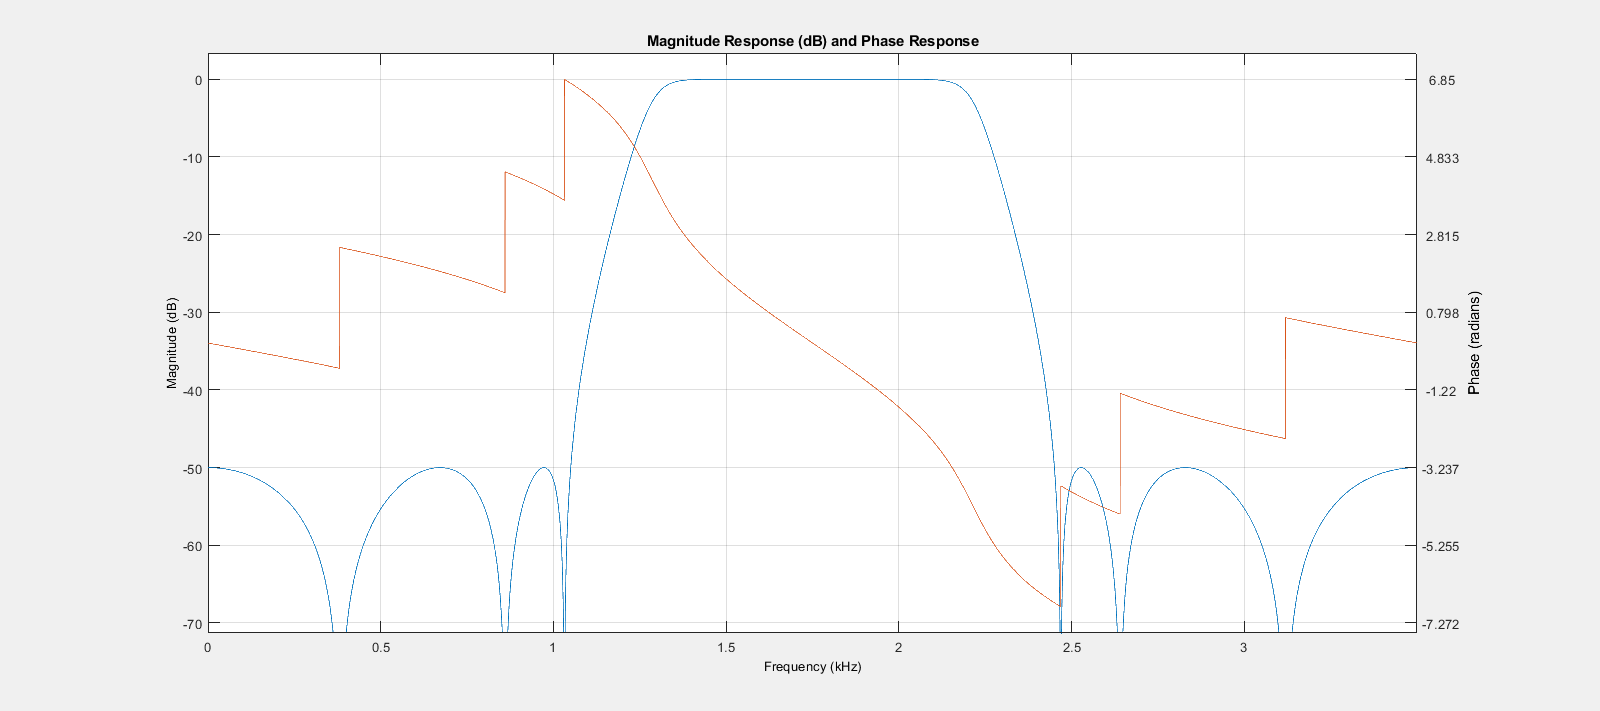

fvtool(BpIIR, 'freq')

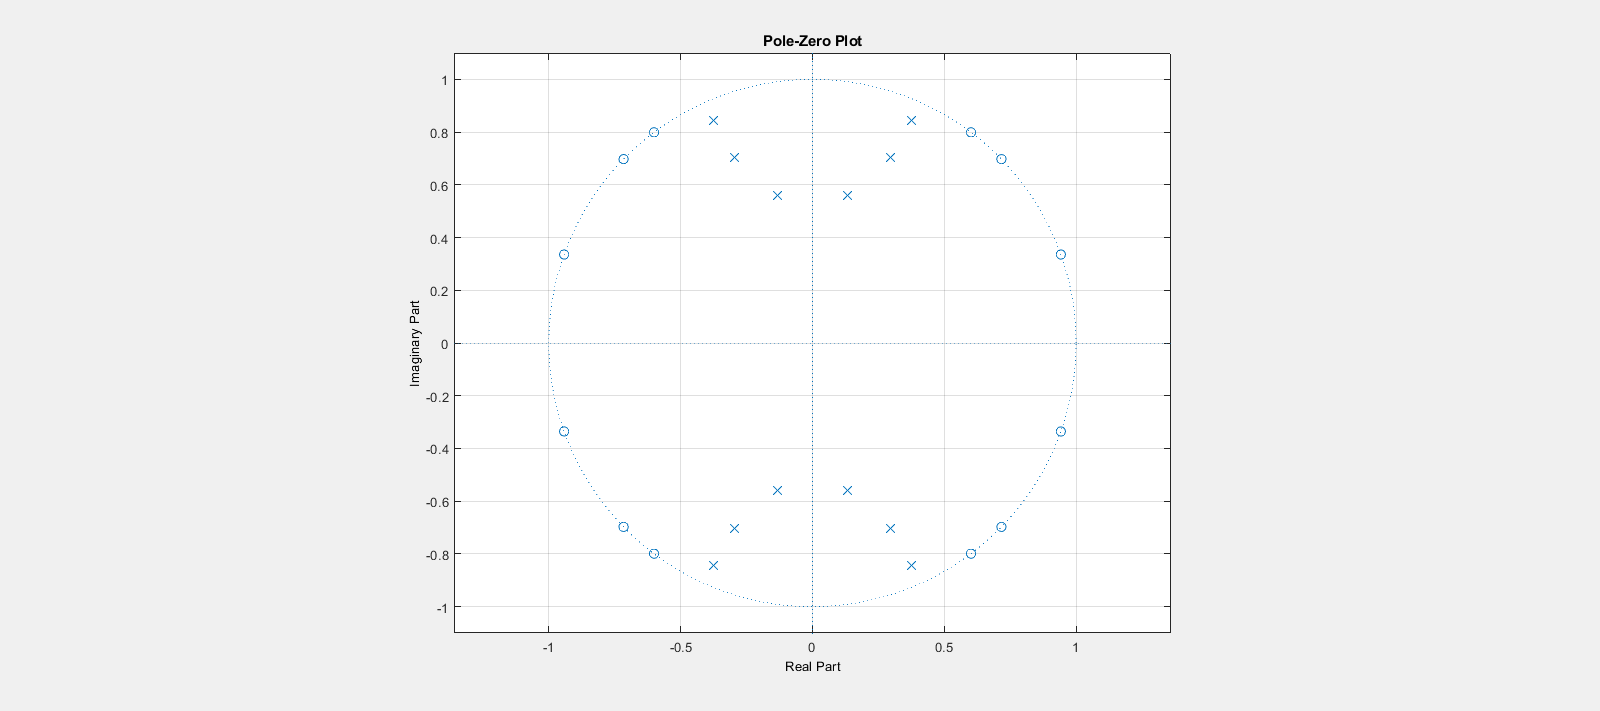

fvtool(BpIIR,'polezero')

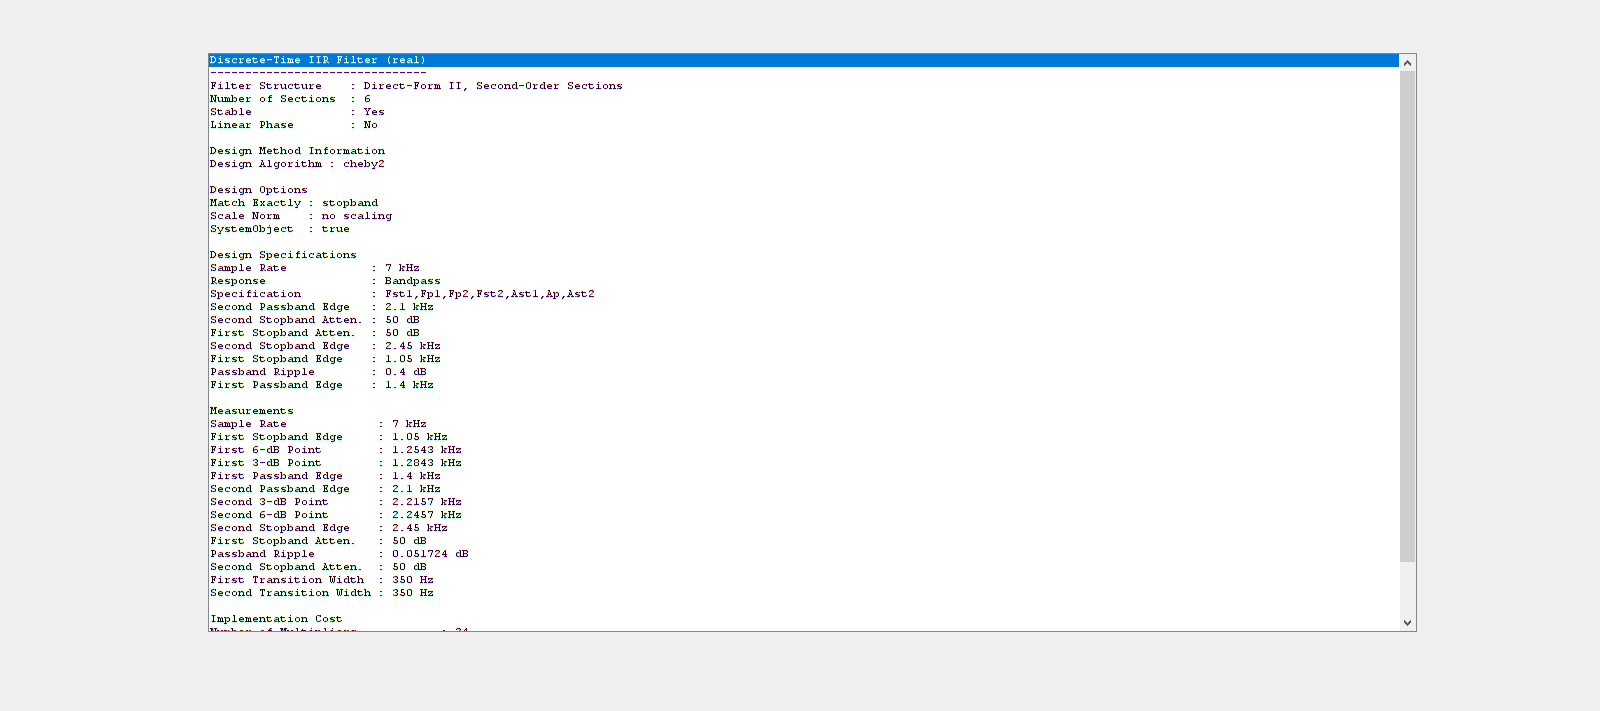

fvtool(BpIIR,'info')

Q3.4]

BpIIR = design(filtSpecs,'ellip','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandpass (Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



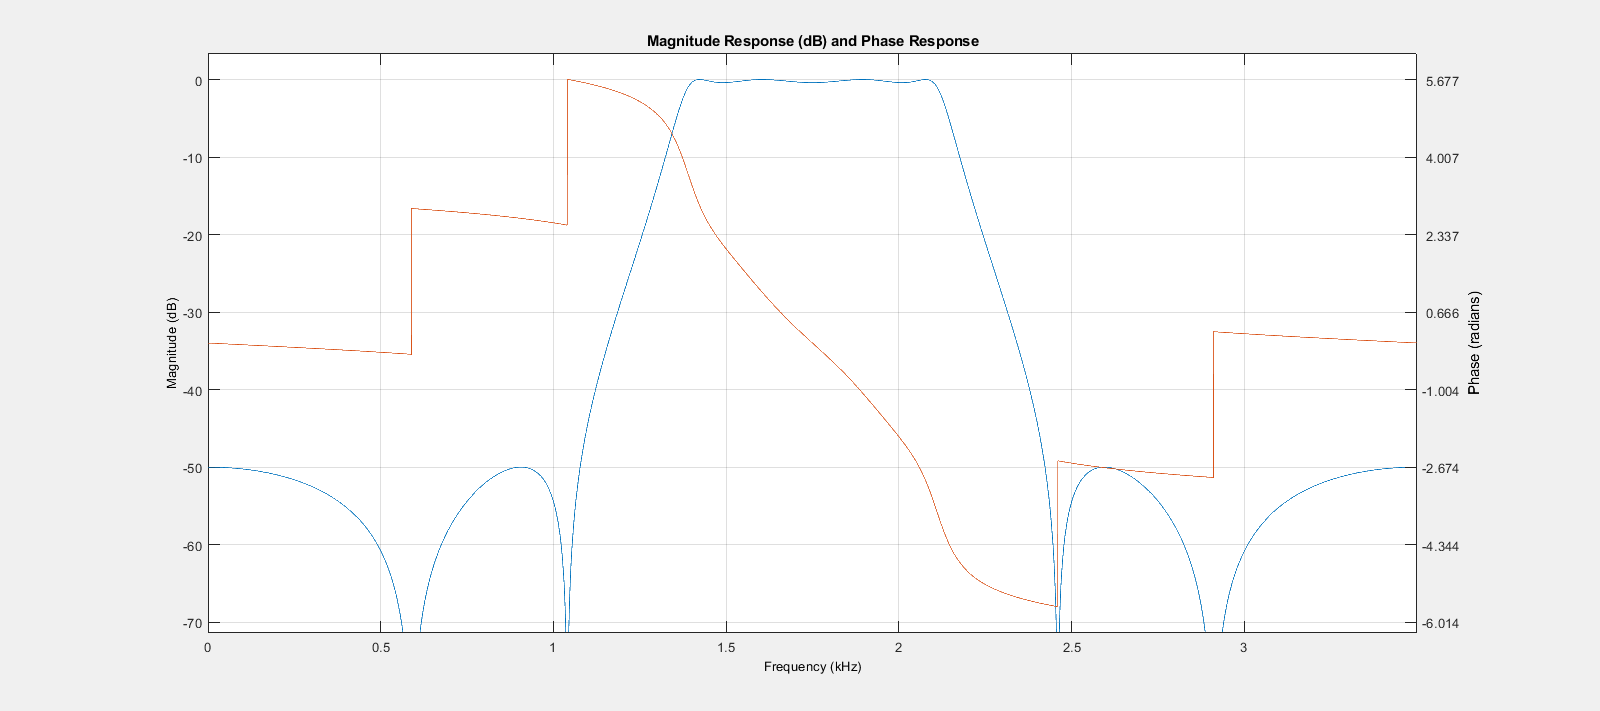

fvtool(BpIIR, 'freq')

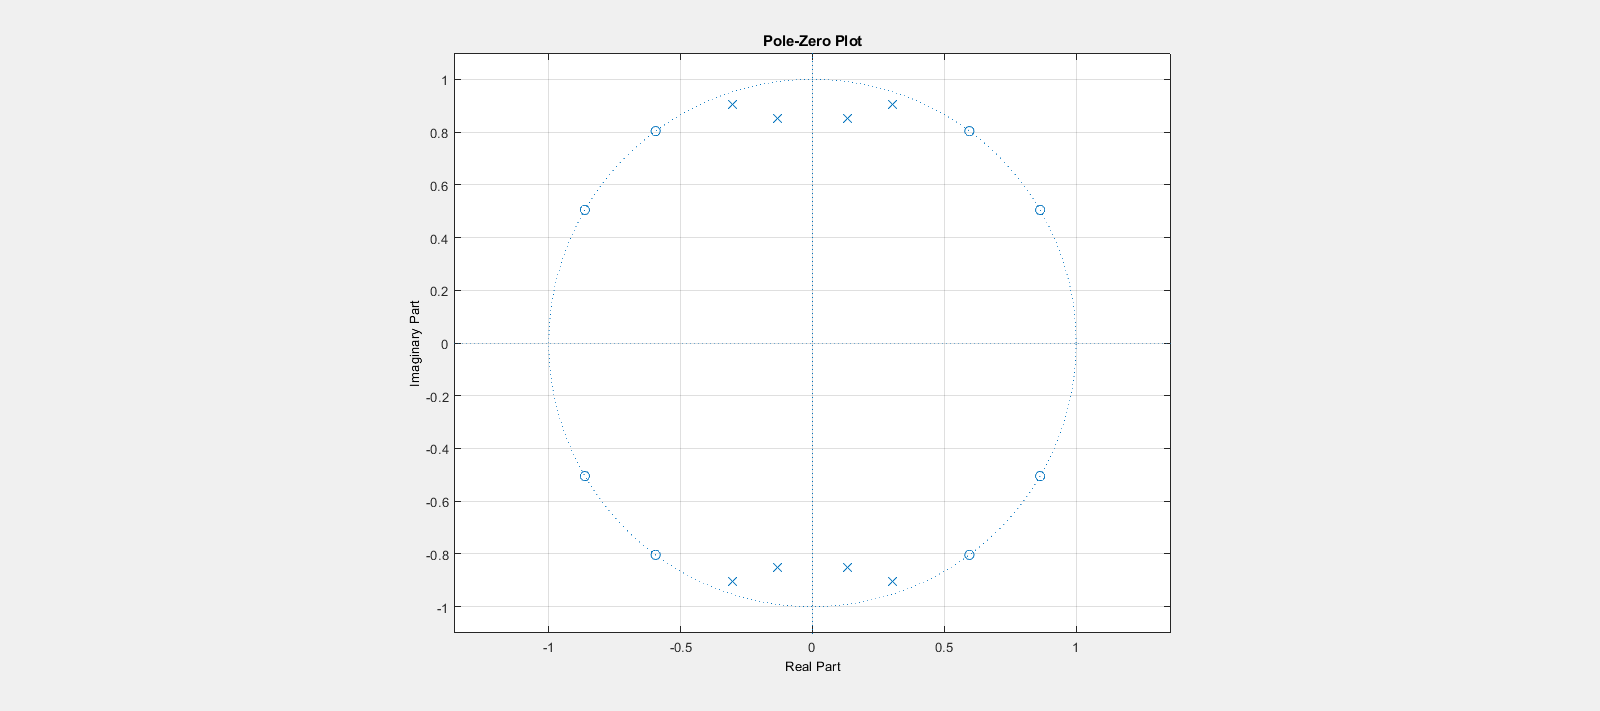

fvtool(BpIIR,'polezero')

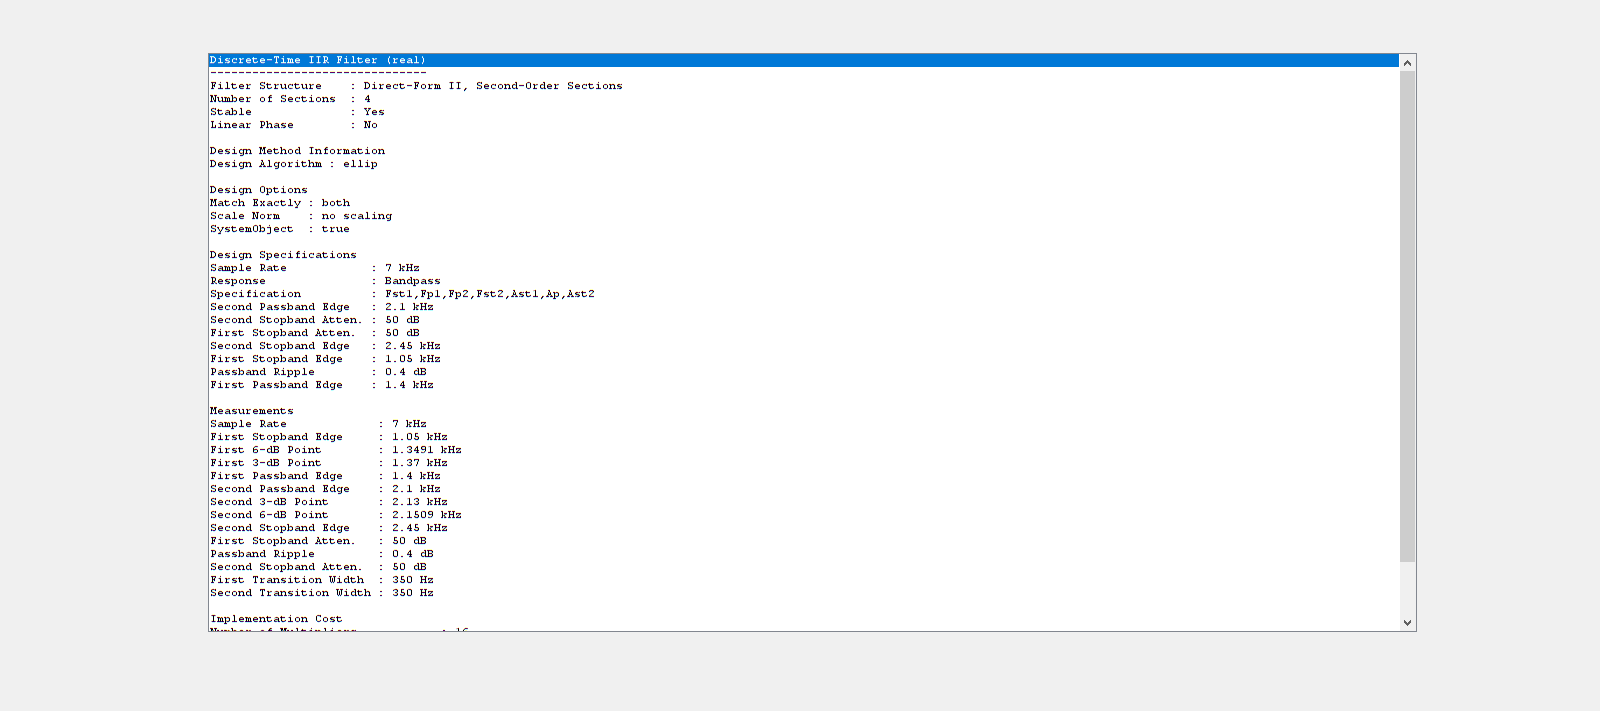

fvtool(BpIIR,'info')

Q4.1]

% Sampling rate and cutoff frequencies
Fs = 12000;
Fpass1 = 2100;
Fpass2 = 4500;
Fstop1 = 2700;
Fstop2 = 3900;

% Pass band ripple and minimum stop band attenuation
Rp = 0.6;
Astop1 = 45;
%Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2
filtSpecs = fdesign.bandstop(Fpass1,Fstop1,Fstop2,Fpass2,Rp,Astop1,Rp,Fs);
BsIIR = design(filtSpecs,'butter','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandstop (Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



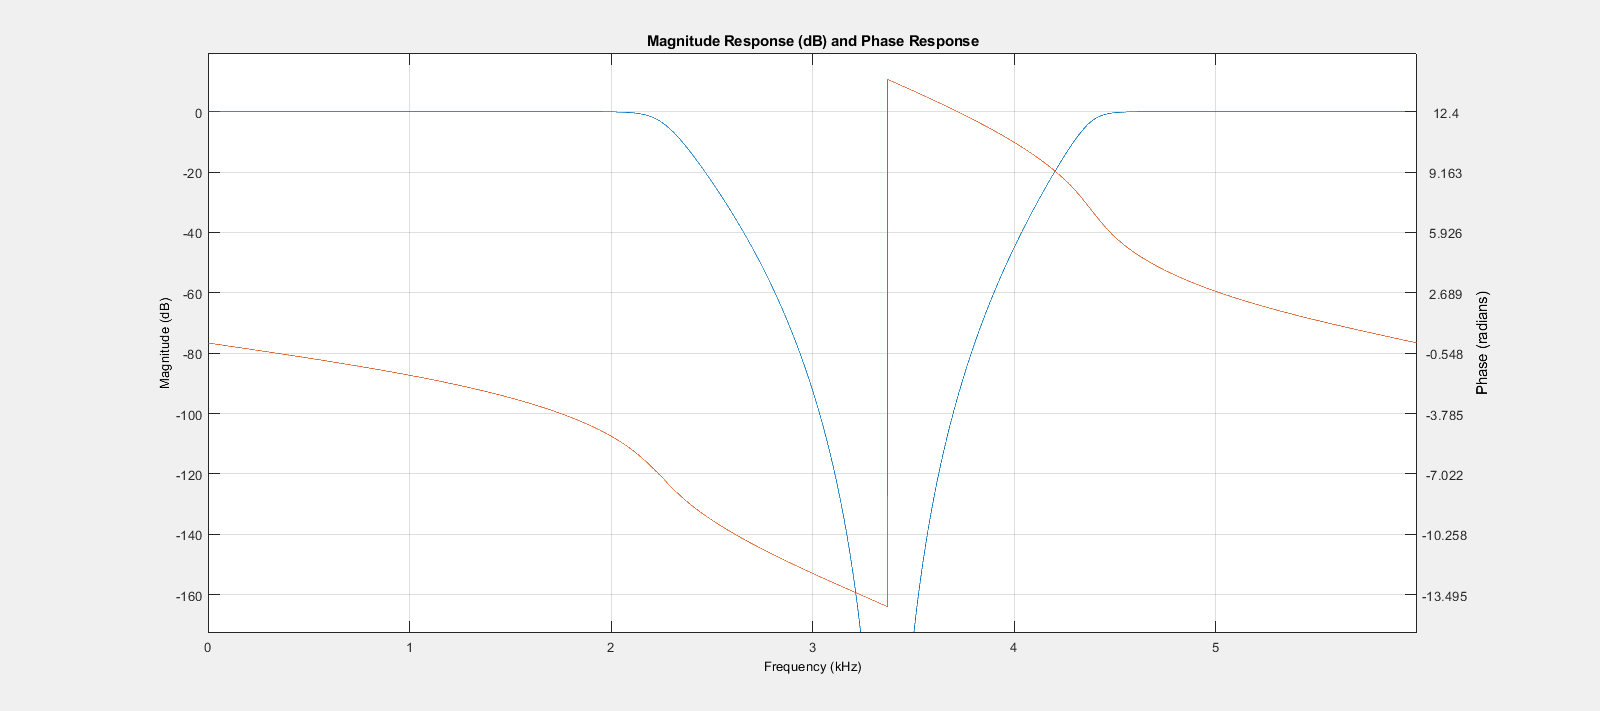

fvtool(BsIIR, 'freq')

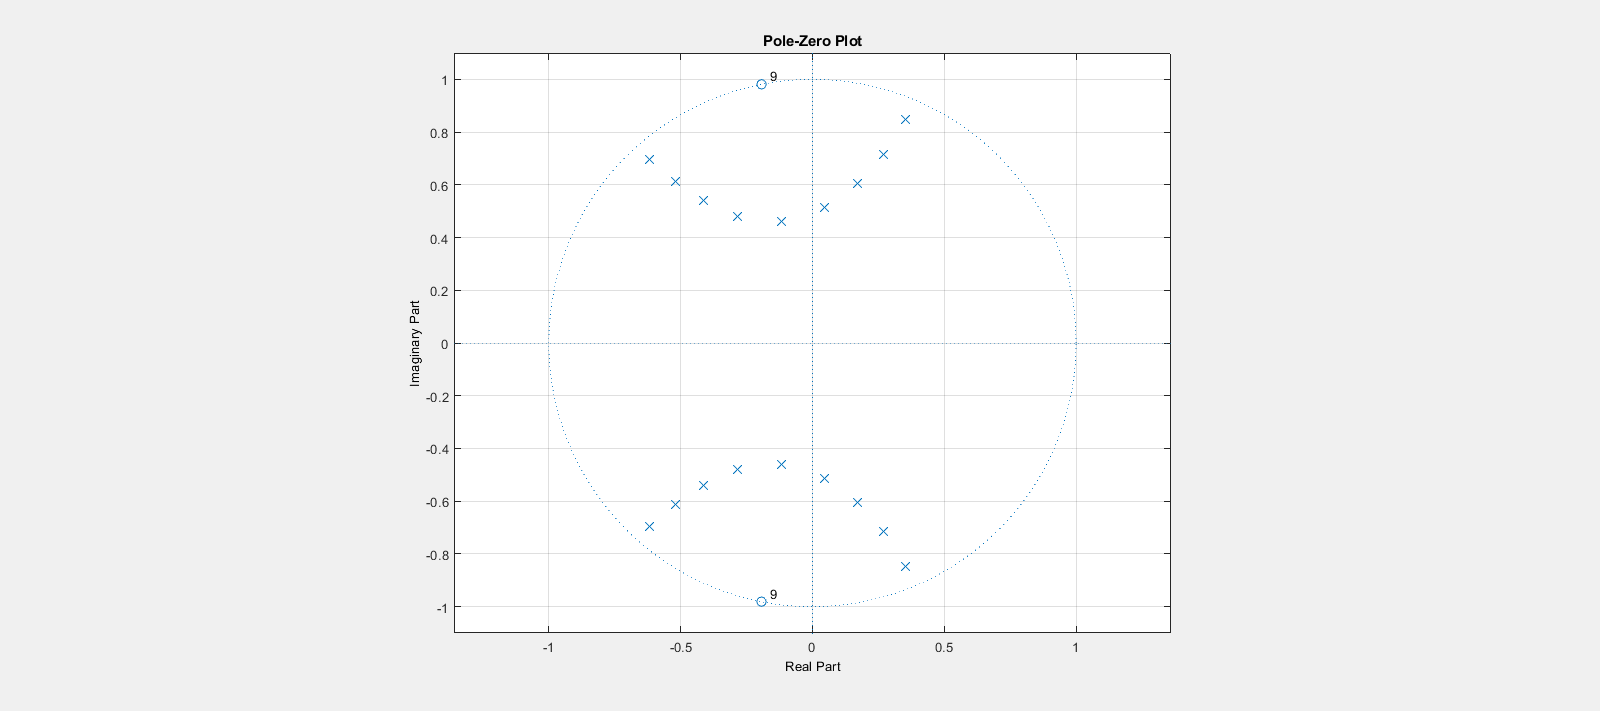

fvtool(BsIIR,'polezero')

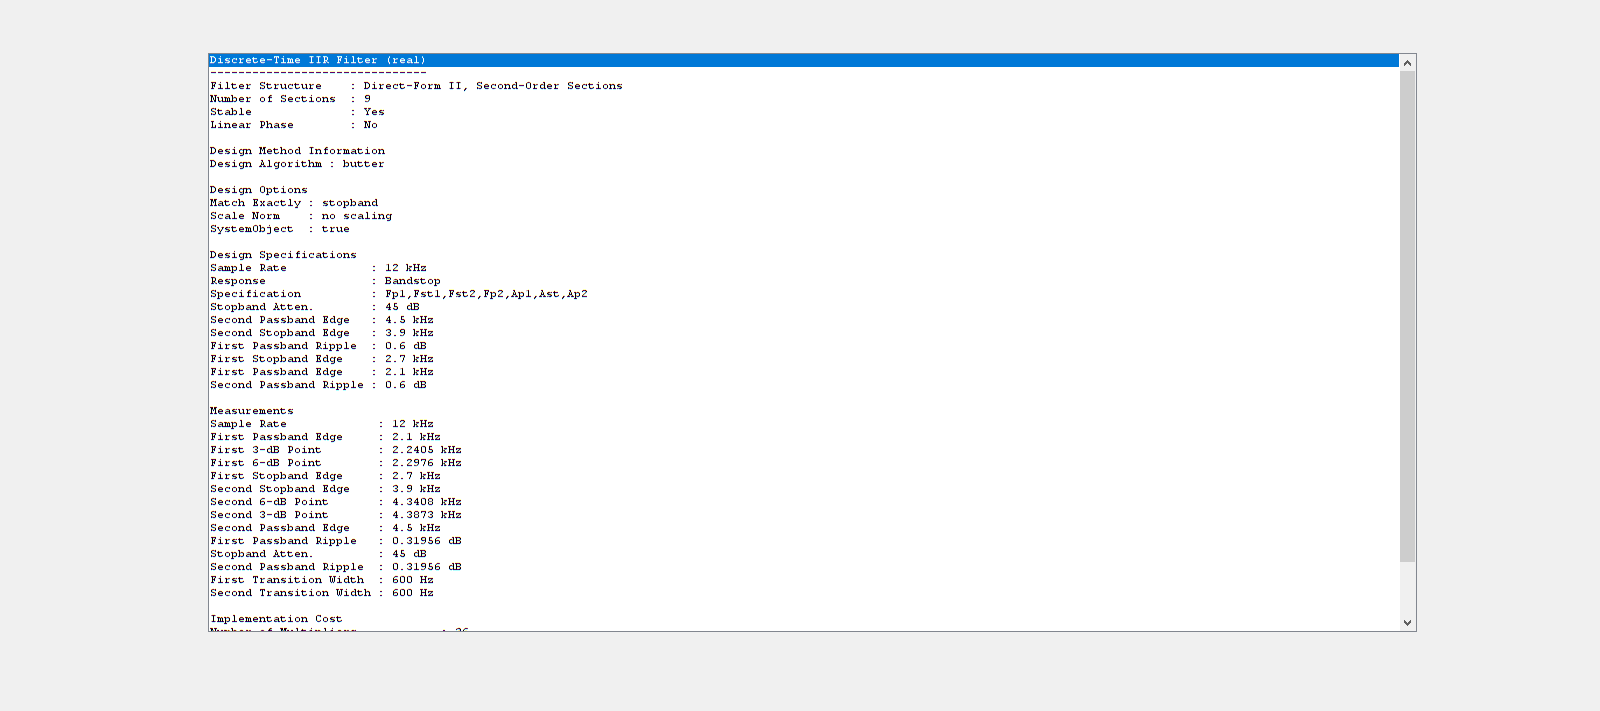

fvtool(BsIIR,'info')

q4.2]

BsIIR = design(filtSpecs,'cheby1','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandstop (Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



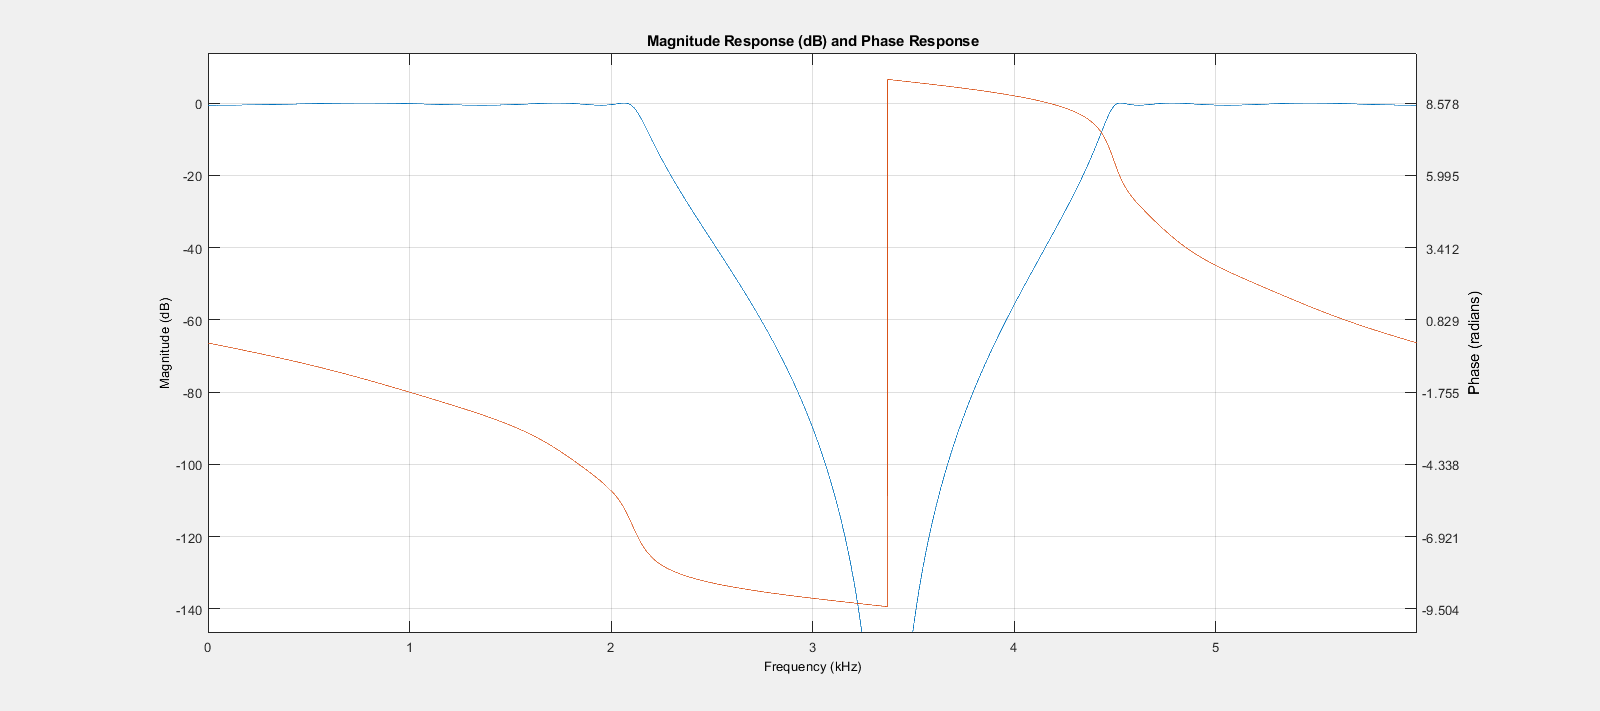

fvtool(BsIIR, 'freq')

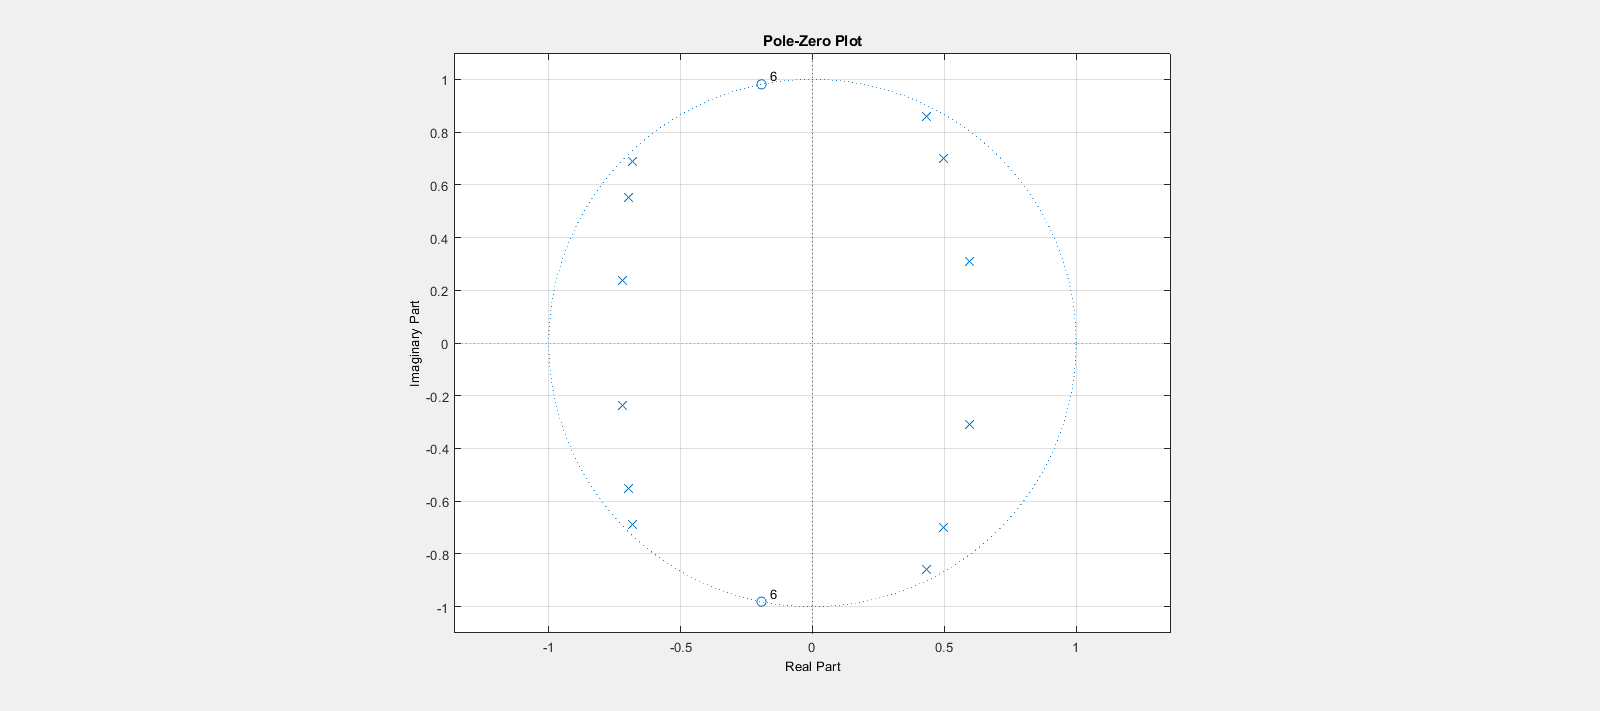

fvtool(BsIIR,'polezero')

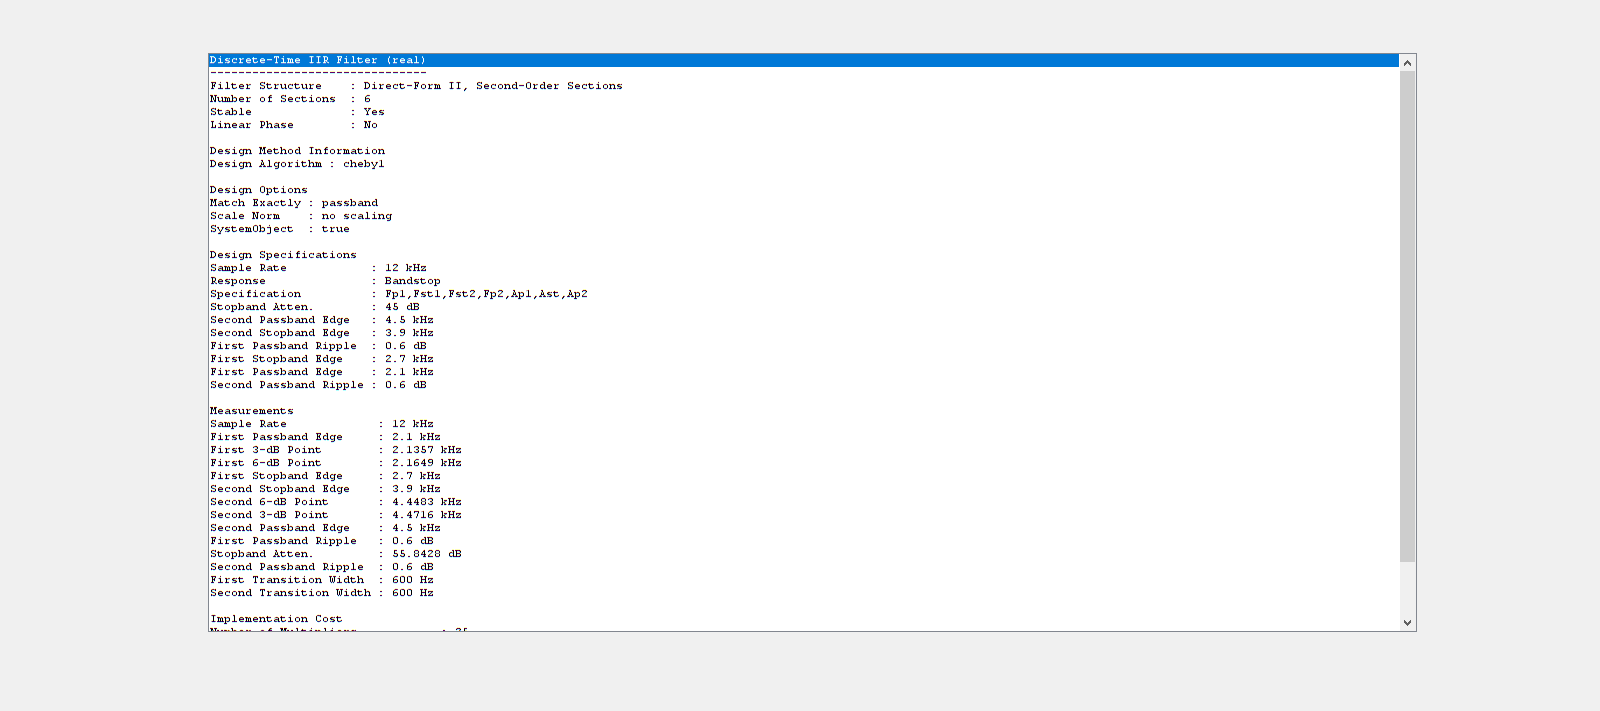

fvtool(BsIIR,'info')

q4.3]

BsIIR = design(filtSpecs,'cheby2','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandstop (Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



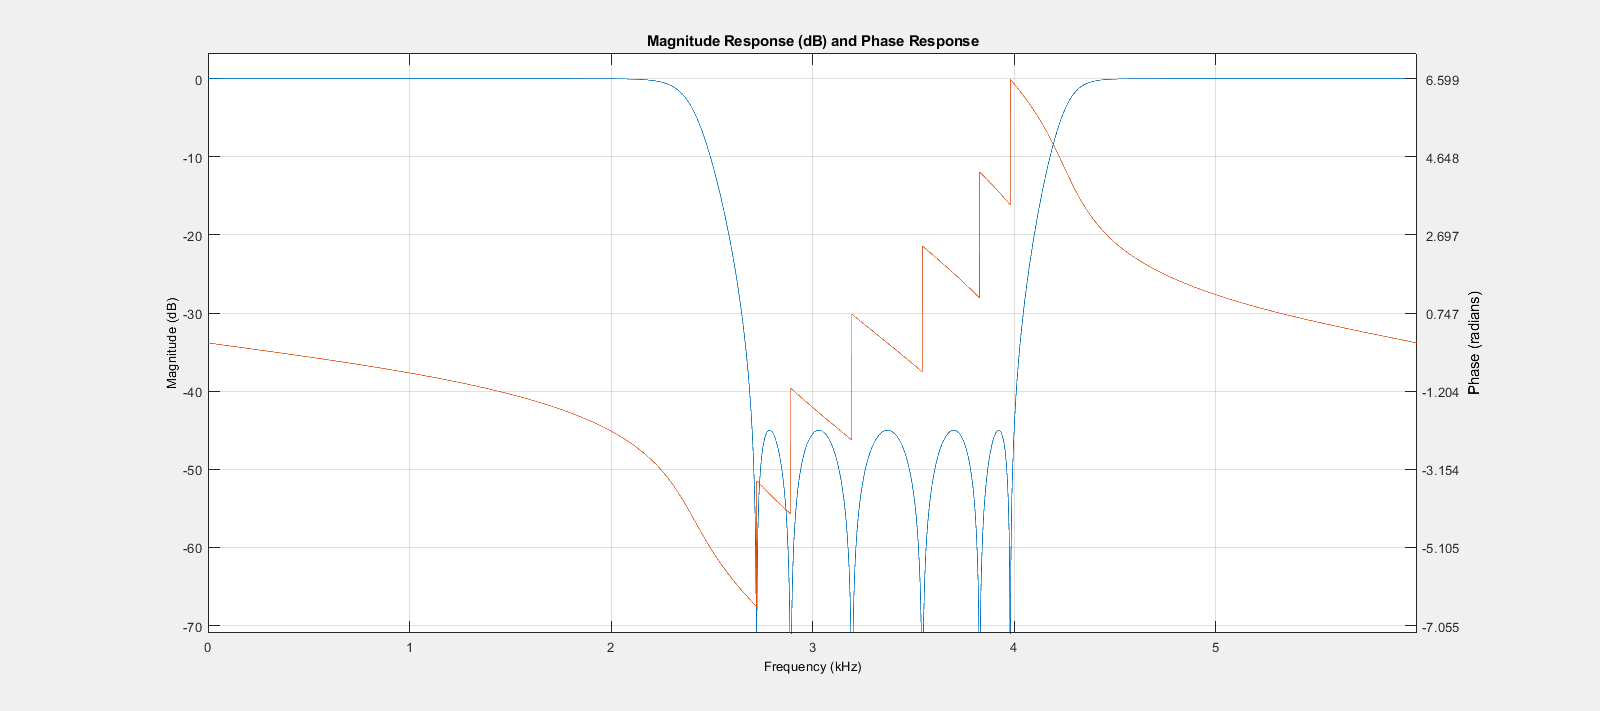

fvtool(BsIIR, 'freq')

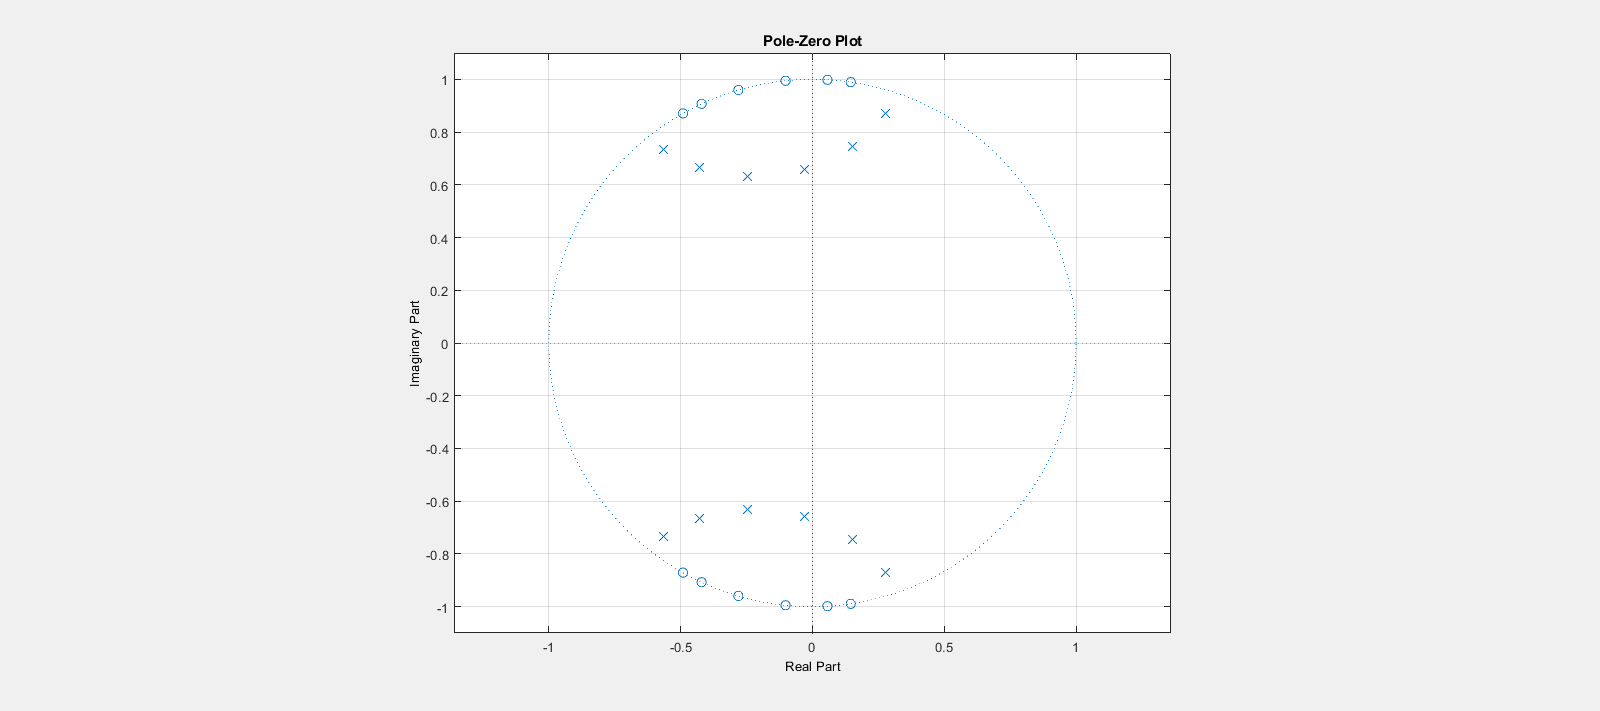

fvtool(BsIIR,'polezero')

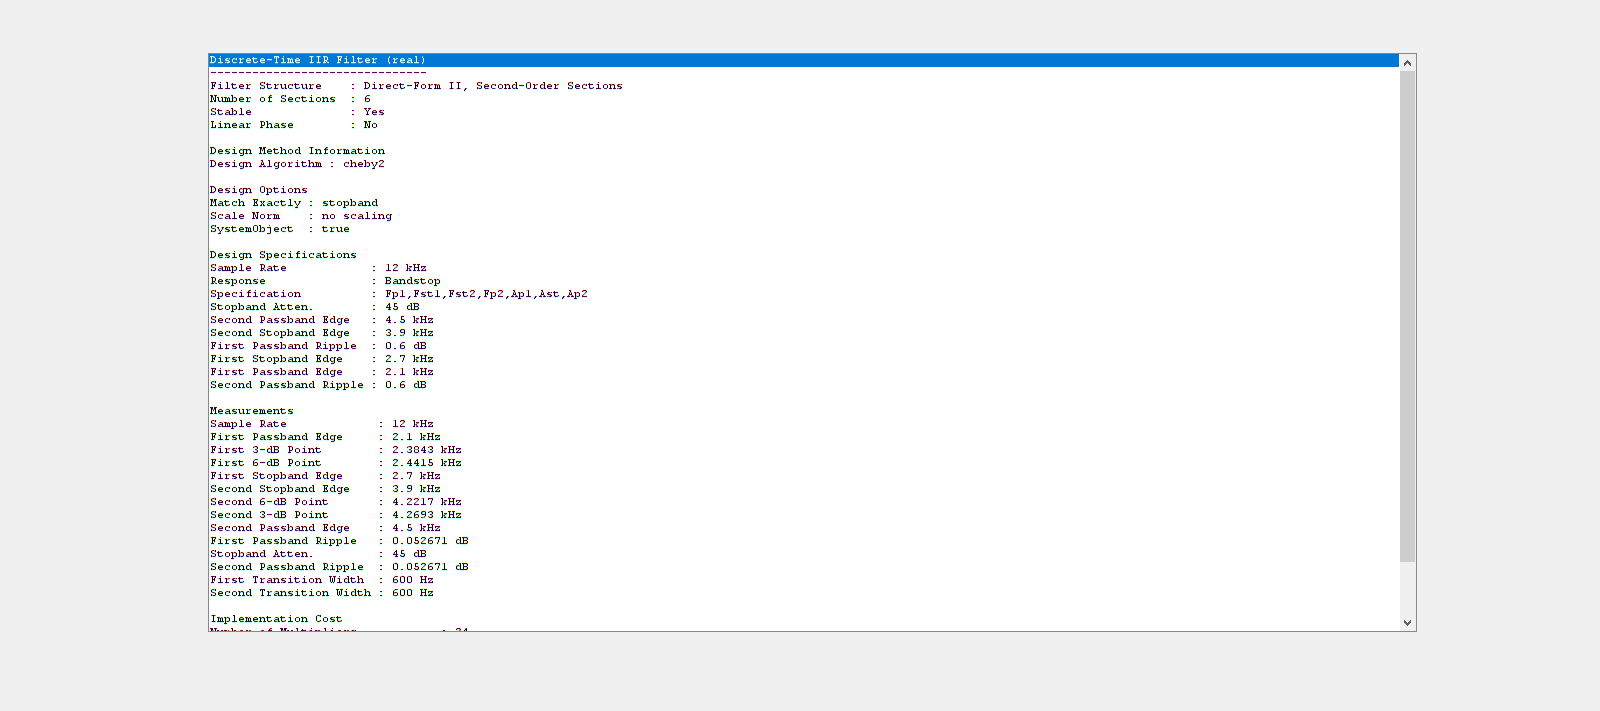

fvtool(BsIIR,'info')

q4.4]

BsIIR = design(filtSpecs,'ellip','SystemObject',true);
designmethods(filtSpecs)



Design Methods for class fdesign.bandstop (Fp1,Fst1,Fst2,Fp2,Ap1,Ast,Ap2):


butter
cheby1
cheby2
ellip
equiripple
kaiserwin



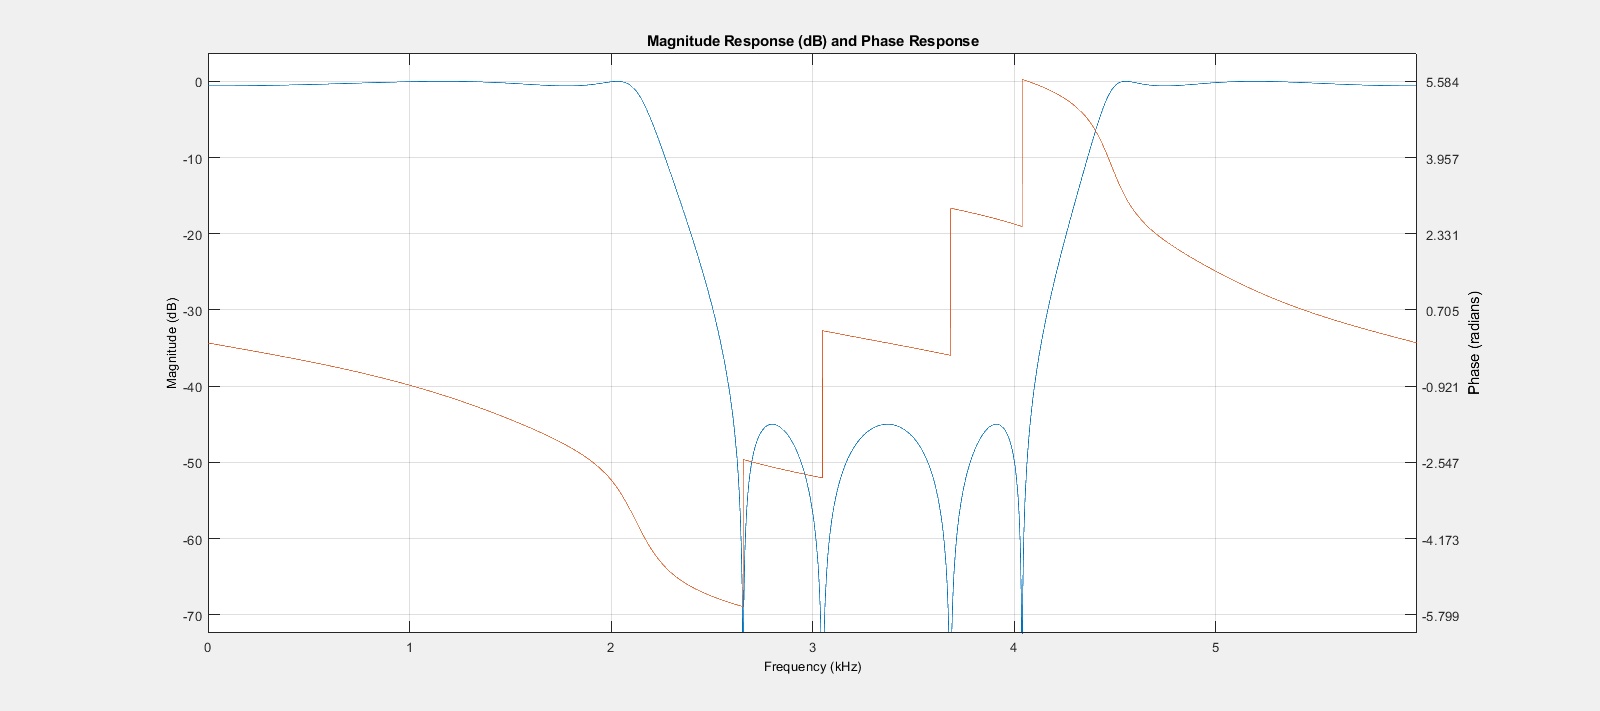

fvtool(BsIIR, 'freq')

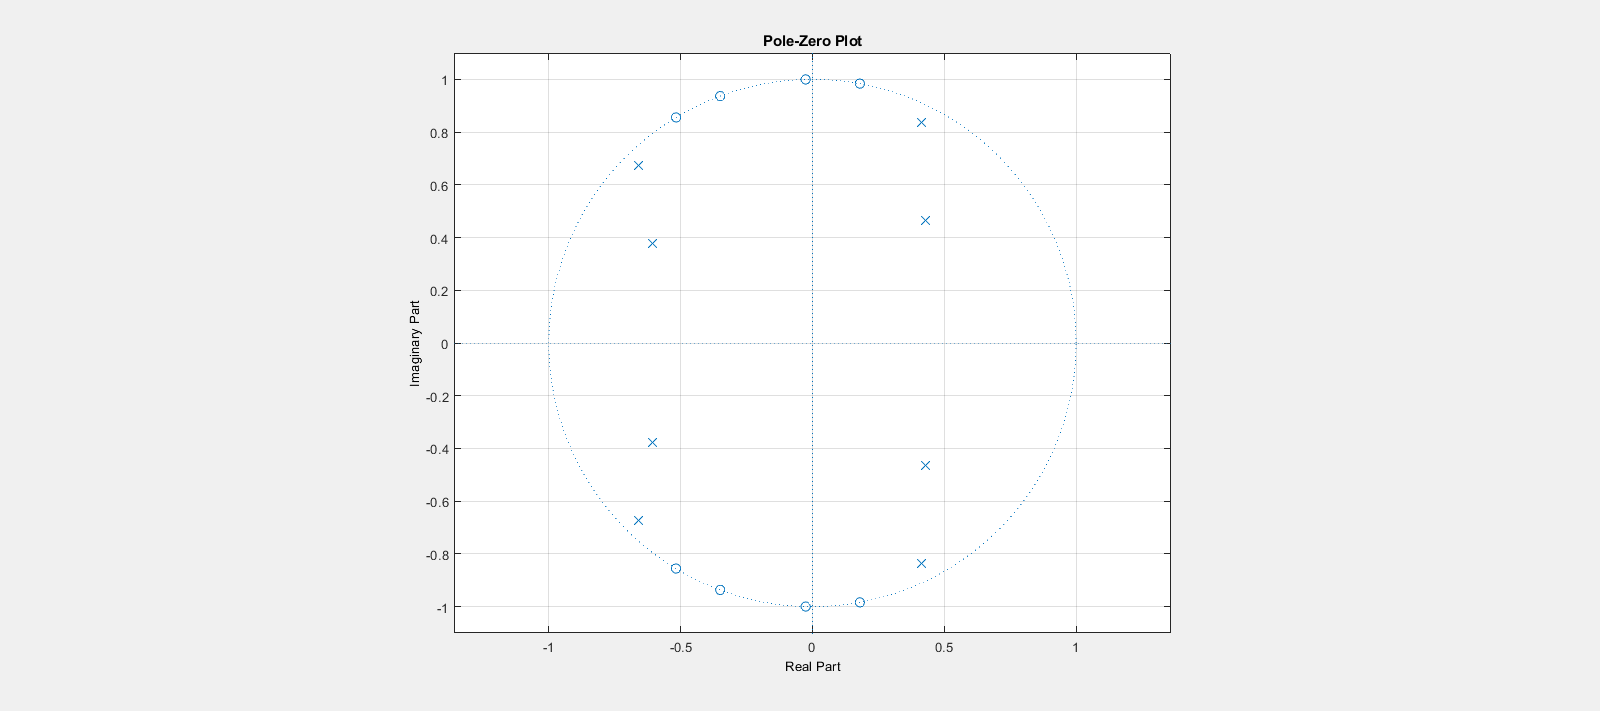

fvtool(BsIIR,'polezero')

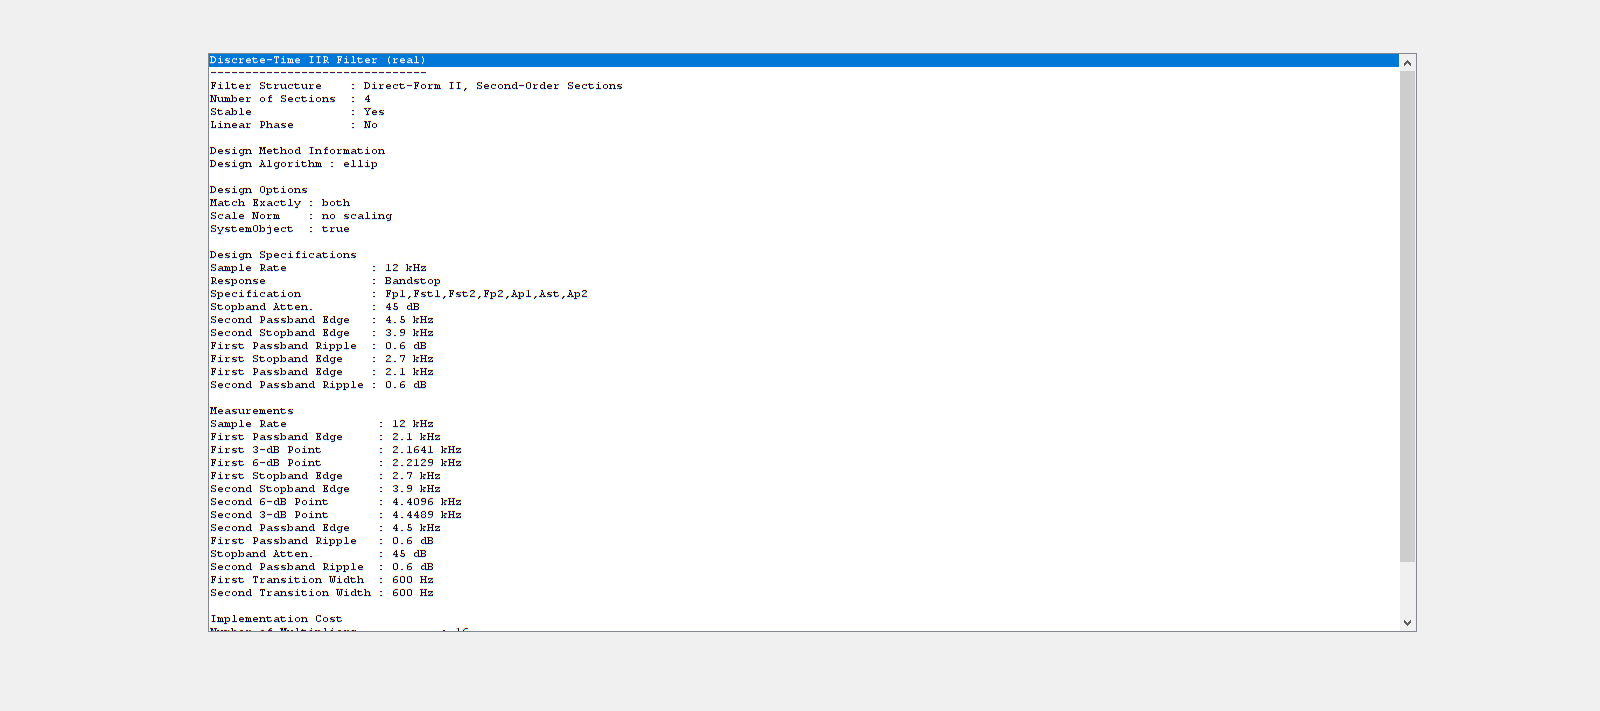

fvtool(BsIIR,'info')